This script will examine some transport properites to compare core, peripheral, and interstitial transports.  You'll need [BetaEddyOne](https://zenodo.org/records/8200056), [jLab](https://github.com/jonathanlilly/jLab), and the [Crameri colormaps](https://www.mathworks.com/matlabcentral/fileexchange/68546-crameri-perceptually-uniform-scientific-colormaps).

%------------------------------------------------------------------------
%Load the data
%This is when your NetCDF file is kept
ncdir='/Users/lilly/Desktop/Dropbox/NetCDF/';
filename='BetaEddyOne.nc';

%loading in data
lato=ncread([ncdir filename],'latitude');
f0=abs(corfreq(lato))/3600; %rad/s

x=ncread([ncdir filename],'x')/1000;%store distances in km
y=ncread([ncdir filename],'y')/1000;%store distances in km
ssh=squeeze(ncread([ncdir filename],'ssh'))*100;%store ssh in cm
u=squeeze(ncread([ncdir filename],'u'))*100;%store velocities in cm/s
v=squeeze(ncread([ncdir filename],'v'))*100;%store velocities in cm/s

%vorticity, shear strain, and normal strain, nondimensionalized by f0
zeta=squeeze(ncread([ncdir filename],'zeta'))/f0;
sigma=squeeze(ncread([ncdir filename],'sigma'))/f0;
nu=squeeze(ncread([ncdir filename],'nu'))/f0;
 
drifter_x=ncread([ncdir filename],'drifter_x')'/1000;%in km
drifter_y=ncread([ncdir filename],'drifter_y')'/1000;%in km 
drifter_u=ncread([ncdir filename],'drifter_u')'*100;%in cm/s
drifter_v=ncread([ncdir filename],'drifter_v')'*100;%in cm/s
%drifter_zeta=ncread([ncdir filename],'drifter_zeta')'./f0;
drifter_t=vrep([1:size(drifter_x,1)]',size(drifter_x,2),2);%time for drifters
%------------------------------------------------------------------------
%Compute eddy center location and largest instanteous closed streamline
[xo,yo]=eddyCenterFromField(x,y,ssh,0.9,method="timesMax");
[xp,yp,sshEddy]=fieldInEddyFrame(x,y,xo,yo,300,ssh);

uo=vdiff(xo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s
vo=vdiff(yo,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s

[psip,psi,psif] = eddyFrameStreamFunction(1000*xp,1000*yp,sshEddy/100,uo/100,vo/100,f0);

tic;
[xpc,ypc,levels,index]=largestClosedStreamline(xp,yp,psip/1000,0.25);
toc
xc=celladd(xpc,xo);%put these contours back in the Earth frame
yc=celladd(ypc,yo);

%finally, mark particles as inside or outside trapping region 
isTrapped=isParticleEnclosed(drifter_x,drifter_y,xc,yc);
%------------------------------------------------------------------------

Let's look at how the various radii change with time. 

[~,~,~,R]=curvemoments(xpc,ypc);
[xzm,yzm]=eddyCenterFromField(x,y,zeta,1,method='timesMin');
[~,~,xzc,yzc]=eddyCenterFromField(x,y,zeta,0,contains={xzm,yzm});
[~,~,~,Rz]=curvemoments(xzc,yzc);

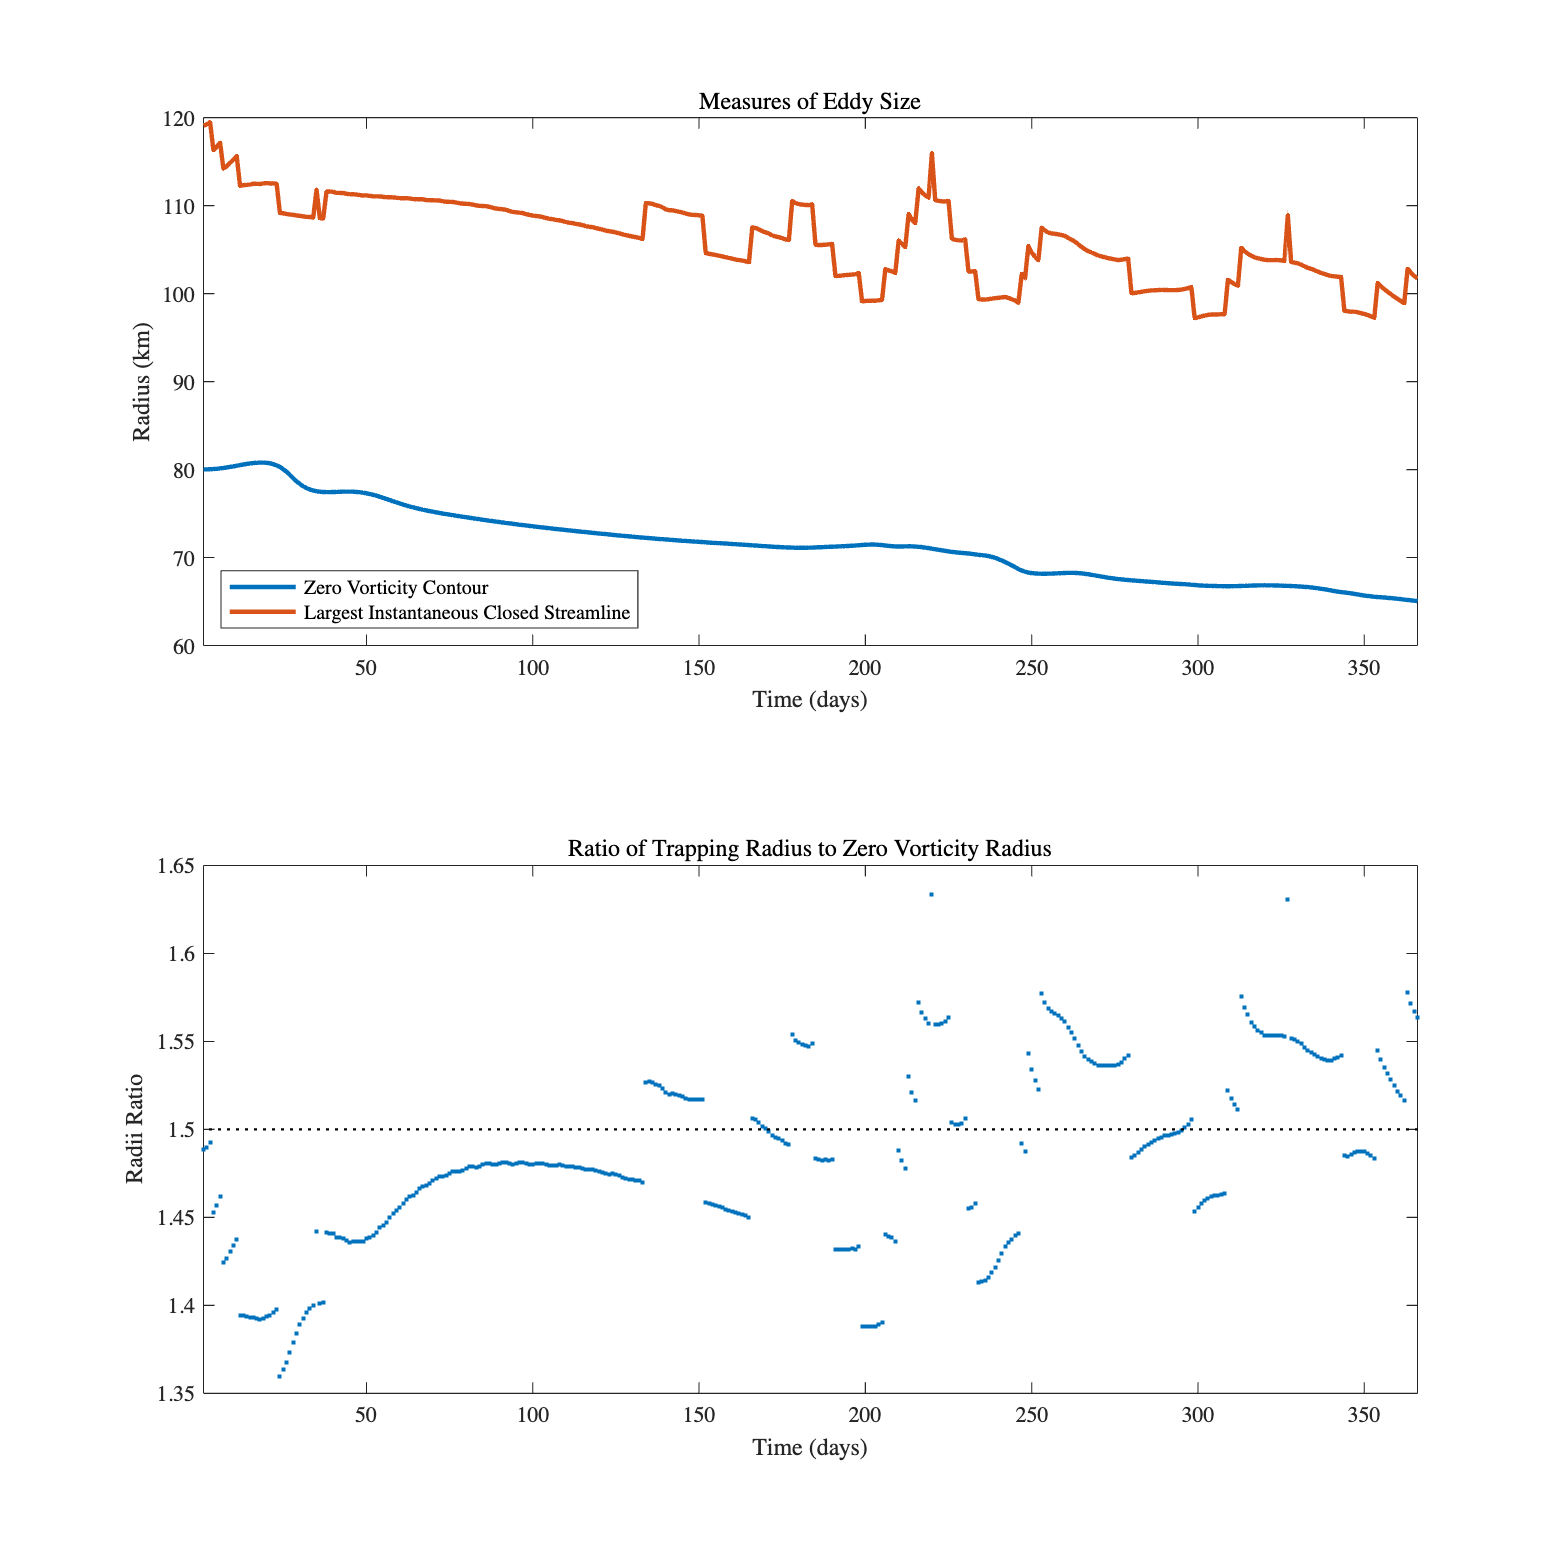

hf = figure();
hf.Position(3:4) = [1200,1200];

tiledlayout(2,1);

nexttile
plot(1:length(R),Rz,linewidth=2);hold on,plot(1:length(R),R,linewidth=2)
ylabel('Radius (km)')
xlabel("Time (days)")
legend("Zero Vorticity Contour","Largest Instantaneous Closed Streamline",'location','southwest')
title('Measures of Eddy Size')
xlim([1 length(R)])

nexttile
plot(1:length(R),R./Rz,'.'),hlines(1.5,'k:')
xlabel("Time (days)")
title('Ratio of Trapping Radius to Zero Vorticity Radius')
ylabel("Radii Ratio")
xlim([1 length(R)])

%Let's look at a trapping histogram
sum(mean(isTrapped,1)==1)./size(isTrapped,2) %always trapped 

ans = 0.0088

sum(mean(isTrapped,1)==0)./size(isTrapped,2) %never trapped

ans = 0.9649

sum(mean(isTrapped,1)~=0&mean(isTrapped,1)~=1)./size(isTrapped,2) %sometimes trapped

ans = 0.0263

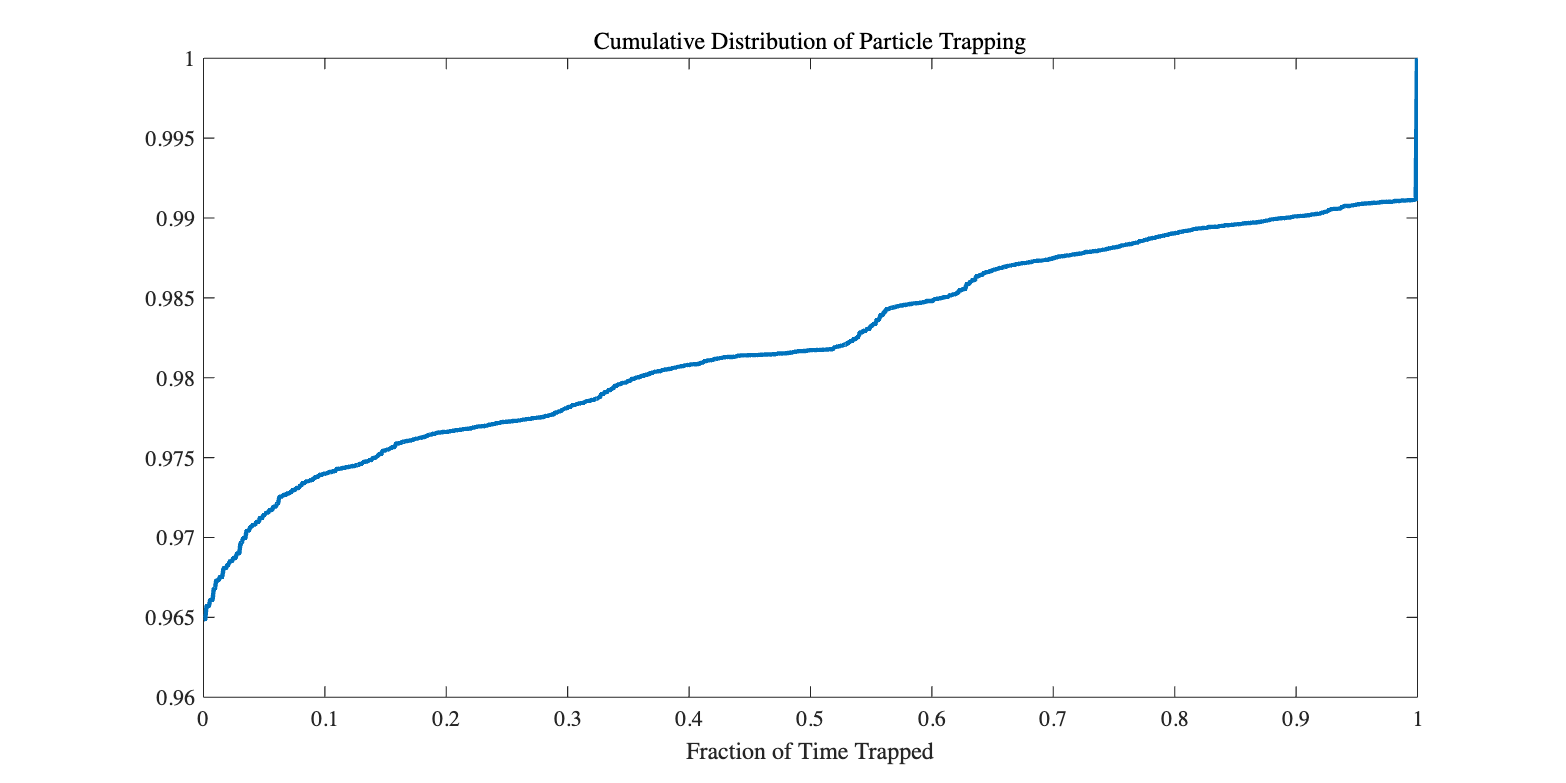


[n,xval]=hist(mean(isTrapped,1),1000);
hf = figure();
hf.Position(3:4) = [1200,600];
plot(xval,cumsum(n)./sum(n),linewidth=2)
title('Cumulative Distribution of Particle Trapping')
xlabel('Fraction of Time Trapped')

Most particle (96.5%) are never trapped.  A little less than one percent (0.88%) are always trapped, and a bit more than two percent (2.6%) are sometimes trapped, according to this definition. 

Let's now compute the transport according to the particle identity using the Lagrangian fields.

dx = x(2)-x(1);%dx in km 
dA = dx.^2     %differential area in km^2, since dx=dy... 15km^2
K = size(u,3); %number of time steps

%total area of fluid
%max(x)*max(y)/1e6 %1.99 Mm^2

%or if I attribute dA to each grid point
%512*256*dA/1e6 %2 Mm^2
%(max(x)+dx)*(max(y)+dx)/1e6 %2 Mm^2

%initial and final areas of the eddy
[~,~,~,R]=curvemoments(xc,yc);
Eo = pi*R(1)^2;   %44564 km^2
Ef = pi*R(end)^2; %32505 km^2

u_avg = reshape(mean(drifter_u,1),length(x),length(y))';
v_avg = reshape(mean(drifter_v,1),length(x),length(y))';

%------------------------------------------------------------------------------------
%east-west transport computations

%area of fluid particles with net east-west motion 
movesEast = (u_avg>0); 
%Ae = sum(movesEast(:),1)*dA/1e6 % 1.23 Mm^2 moving east
%Aw = sum(~movesEast(:),1)*dA/1e6 % 0.77 Mm^2 moving west

%what is the transport? 
%sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/(2e6) %41 km/year
%sum(u_avg(~movesEast),1)*dA*(1/1000*24*3600*365)/(2e6) %-41 km/year
%a volume of fluid equal to the entire domain size moves 41 km east or west in a year 

%transport expressed in terms of intial eddy area 
%sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/Eo %1852 km/year
%sum(u_avg(~movesEast),1)*dA*(1/1000*24*3600*365)/Eo %1852 km/year

%Let's compare this with distance the eddy moves
%xo(end)-xo(1) %-1164 km/year

%So the total transport due to the eddy is about 1.5x what you would expect
%based only on the transport from what is inside the core 

%sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/Eo/(xo(end)-xo(1)) %1.59

%how far do the areas of eastward and westward moving fluid move?  
%sum(u_avg(movesEast),1)*dA*(1/1000*24*3600*365)/(Ae*1e6)  %67 km/year
%sum(u_avg(~movesEast),1)*dA*(1/1000*24*3600*365)/(Aw*1e6) %-107 km/year

%the volume of westward-moving fluid is about 1/2 as large but moves 2x as far
%------------------------------------------------------------------------------------
%north-south transport computations

%area of fluid particles with net north-south motion 
movesNorth = (v_avg>0); 
%An = sum(movesNorth(:),1)*dA/1e6 % 1.09 Mm^2 moving north
%As = sum(~movesNorth(:),1)*dA/1e6 % 0.91 Mm^2 moving south

%what is the transport? 
%sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/(2e6) %18 km/year
%sum(v_avg(~movesNorth),1)*dA*(1/1000*24*3600*365)/(2e6) %-18 km/year
%a volume of fluid equal to the entire domain size moves 18 km east or west in a year 

%transport expressed in terms of intial eddy area 
%sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/Eo %818 km/year
%sum(v_avg(~movesNorth),1)*dA*(1/1000*24*3600*365)/Eo %819 km/year

%Let's compare this with distance the eddy moves
%yo(end)-yo(1) %-210 km/year

%So the total transport due to the eddy is about 4x what you would expect
%based only on the transport from what is inside the core 

%sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/Eo/(yo(end)-yo(1)) %3.9

%how far do the areas of eastward and westward moving fluid move?  
%sum(v_avg(movesNorth),1)*dA*(1/1000*24*3600*365)/(An*1e6)  %33 km/year
%sum(v_avg(~movesNorth),1)*dA*(1/1000*24*3600*365)/(As*1e6) %-40 km/year

%the volume of northward moving fluid is only slightly larger than that of 
%southward moving fluid, hence the net transport are comparable
%------------------------------------------------------------------------------------

The takeaway: net north-south displacement is about 1/2 as large as net east-west dispacement, perhaps surprisingly.  

Let's visualize the dispacements according to the initial particle locations. 

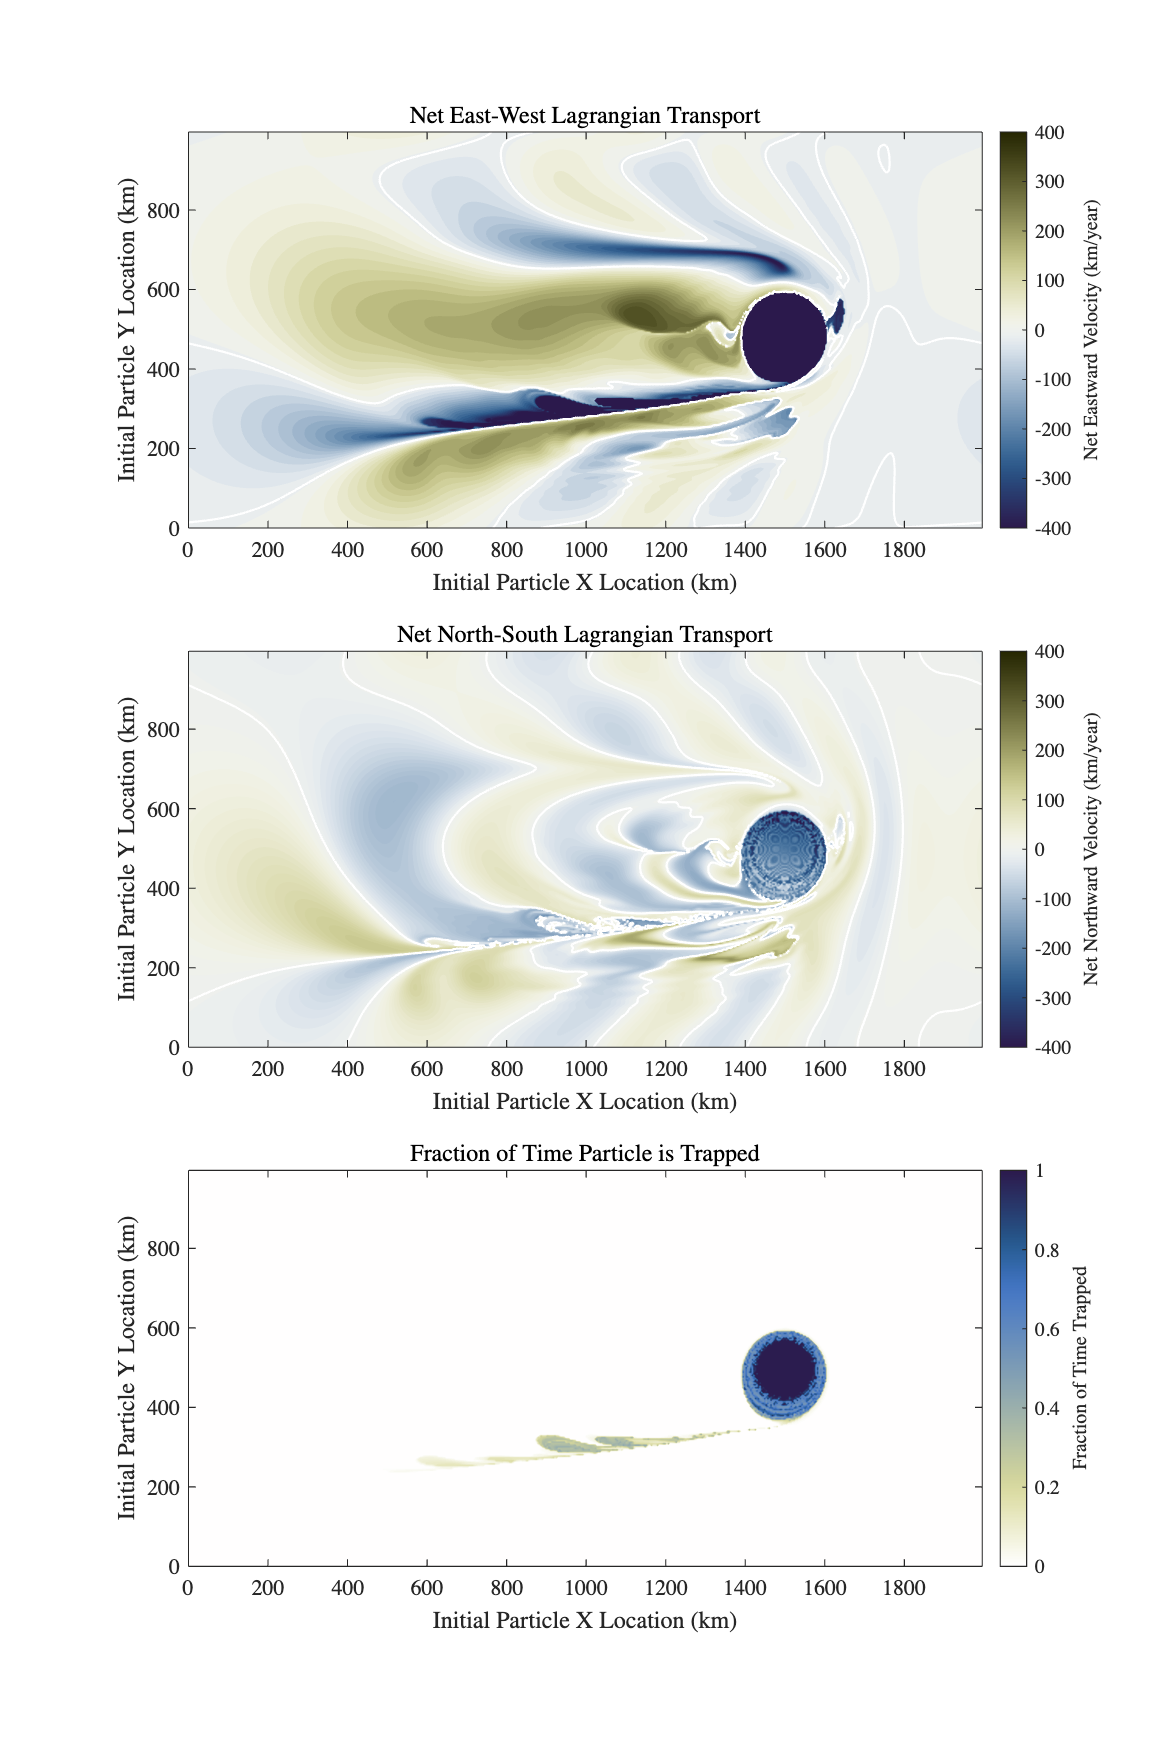

%the fraction of time a particle is within the largest closed streamline
trapFraction = reshape(mean(isTrapped,1),length(x),length(y))';

hf = figure();
hf.Position(3:4) = [1200,1200*3/2];
colormap(crameri('broc'))

tiledlayout(3,1);

nexttile;
contourf(x,y,u_avg*(24*3600*365)/1000/100,100),nocontours, hold on, axis equal 
contour(x,y,u_avg*(24*3600*365)/1000/100,[0 0],'w',linewidth=1)
hc=colorbar('location','EastOutside');
hc.Label.String = "Net Eastward Velocity (km/year)";
title("Net East-West Lagrangian Transport")
clim([-400 400])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')

nexttile;
contourf(x,y,v_avg*(24*3600*365)/1000/100,100),nocontours, hold on, axis equal 
contour(x,y,v_avg*(24*3600*365)/1000/100,[0 0],'w',linewidth=1)
hc=colorbar('location','EastOutside');
hc.Label.String = "Net Northward Velocity (km/year)";
title("Net North-South Lagrangian Transport")
clim([-400 400])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')

ax=nexttile;
contourf(x,y,trapFraction,100),nocontours, hold on, axis equal 
hc=colorbar('location','EastOutside');
hc.Label.String = "Fraction of Time Trapped";
title("Fraction of Time Particle is Trapped")
clim([0 1])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')
colormap(ax,flipud(crameri('davos')))

Note the distinction between the amount of fluid that is trapped and the amount exhibiting systematic east-west or north-south motions. Natrually the eastward-moving fluid is not trapped, but much west-ward moving fluid is not trapped, either.  

Furthermore, whereas the north-south transport of the ambient fluid largely occurs along alternating stripes, the east-west transport regime really depends on the initial location relative to the eddy.  Roughly speaking, things at the same initial latitude as the eddy, which it must displace, will move eastward.  There are also prominent zonal bands of westward transport on the eddy flanks, and one band of prominent eastward transport on the south side of the eddy wake.  This complex behavior suggests several different modes of mediating east-west transport. 

%distance to final location
d = sqrt((drifter_x(end,:)-drifter_x(1,:)).^2+(drifter_y(end,:)-drifter_y(1,:)).^2);
d = reshape(mean(d,1),length(x),length(y))';

% %angle to final location
% theta = angle(drifter_x(end,:)+1i*drifter_y(end,:)-(drifter_x(1,:)+1i*drifter_y(1,:)));
% theta = reshape(theta,length(x),length(y))';

%minimum distance to eddy center 
mindist = min(sqrt((drifter_x-xo).^2+(drifter_y-yo).^2),[],1);
mindist = reshape(mean(mindist,1),length(x),length(y))';

%angle to eddy center 
dtheta = unwrap(angle((xo+1i*yo)-(drifter_x+1i*drifter_y)),[],1);
Norbits = reshape(dtheta(end,:)-dtheta(1,:),length(x),length(y))'/2/pi;

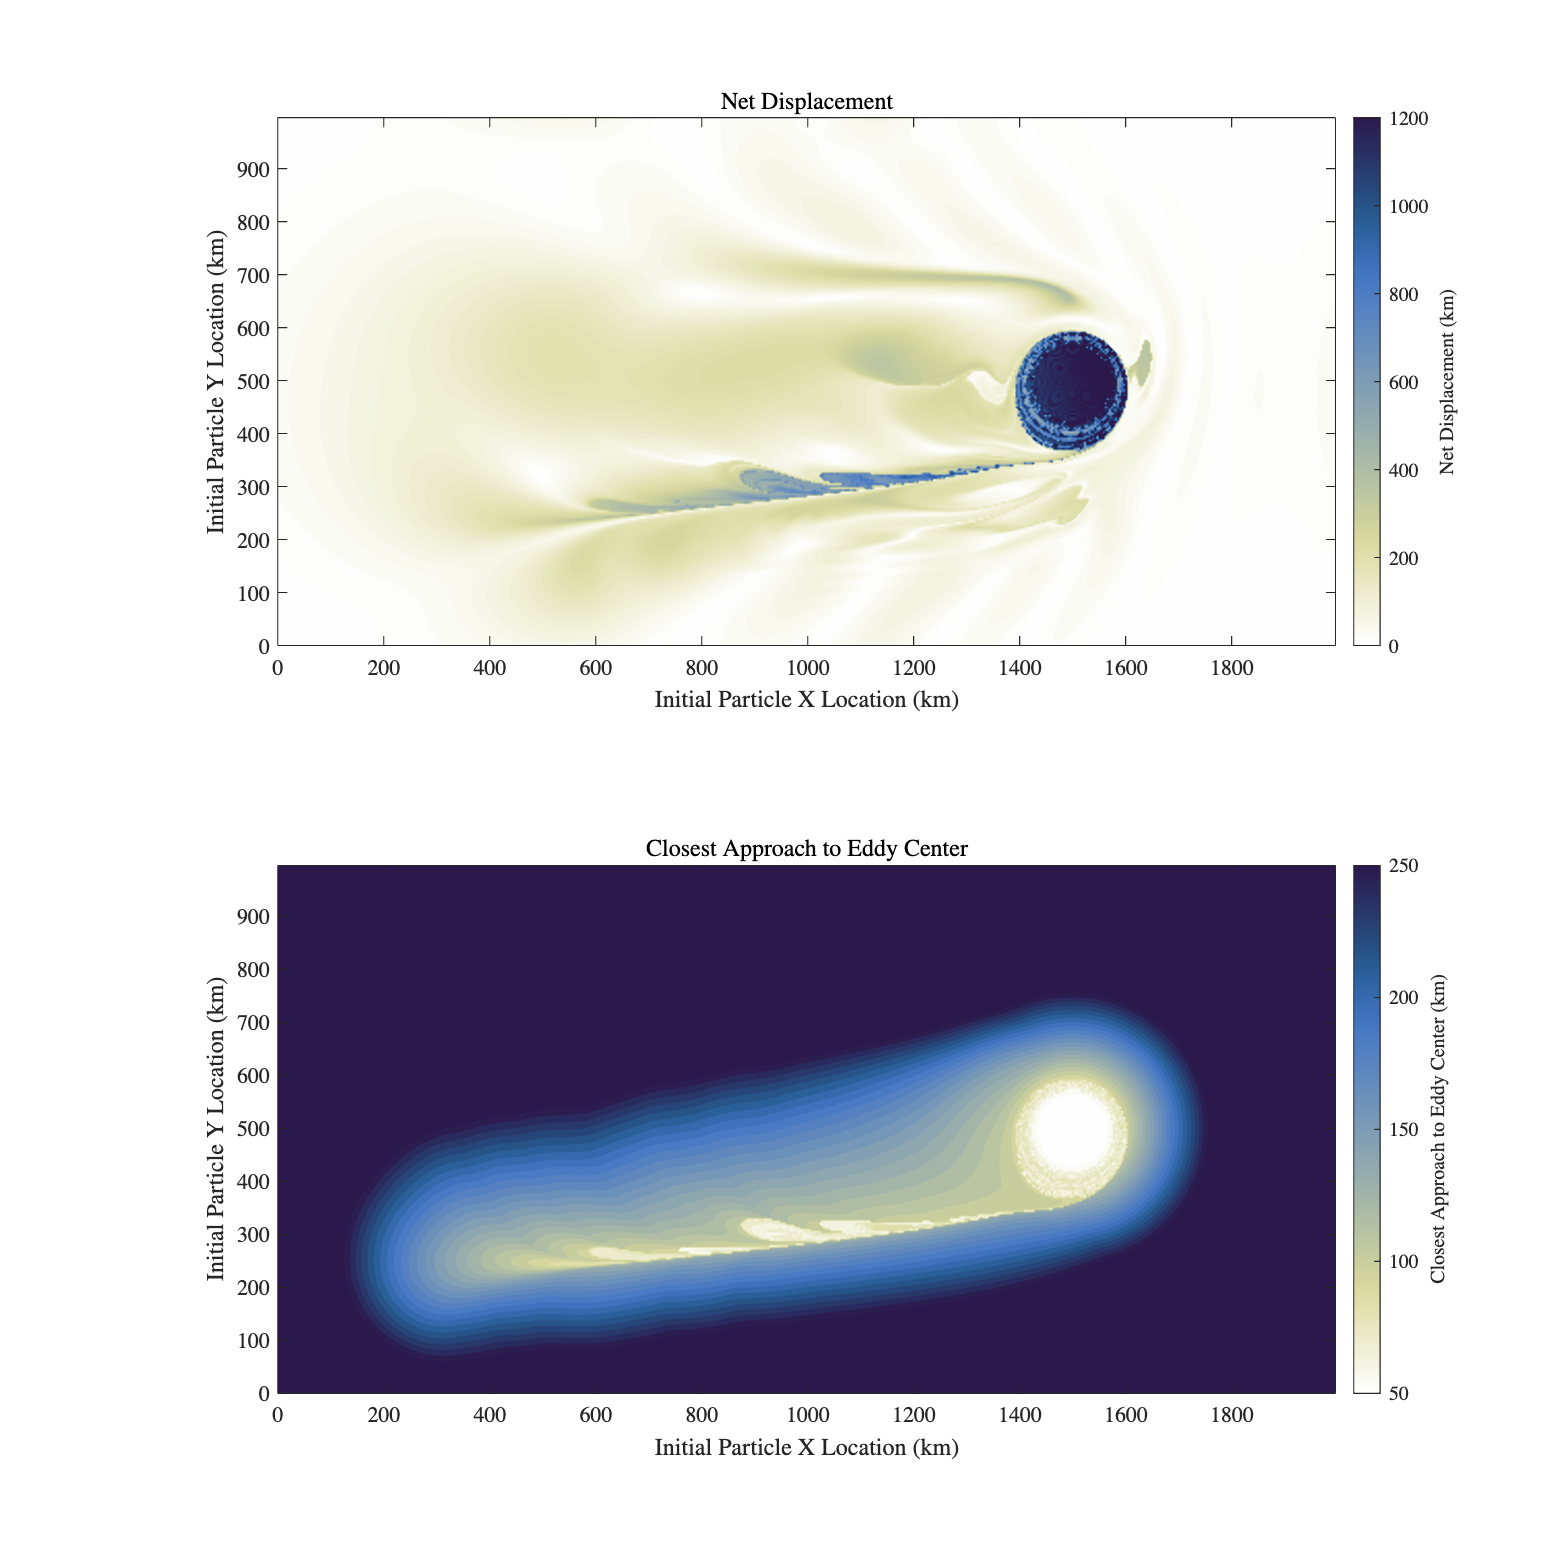

hf = figure();
hf.Position(3:4) = [1200,1200];
colormap(flipud(crameri('davos')))

tiledlayout(2,1);

nexttile;
contourf(x,y,d,100),nocontours, hold on, axis equal 
hc=colorbar('location','EastOutside');
hc.Label.String = "Net Displacement (km)";
title("Net Displacement")
clim([0 1200])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')


nexttile;
contourf(x,y,mindist,100),nocontours, hold on, axis equal 
hc=colorbar('location','EastOutside');
hc.Label.String = "Closest Approach to Eddy Center (km)";
title("Closest Approach to Eddy Center")
clim([50 250])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')

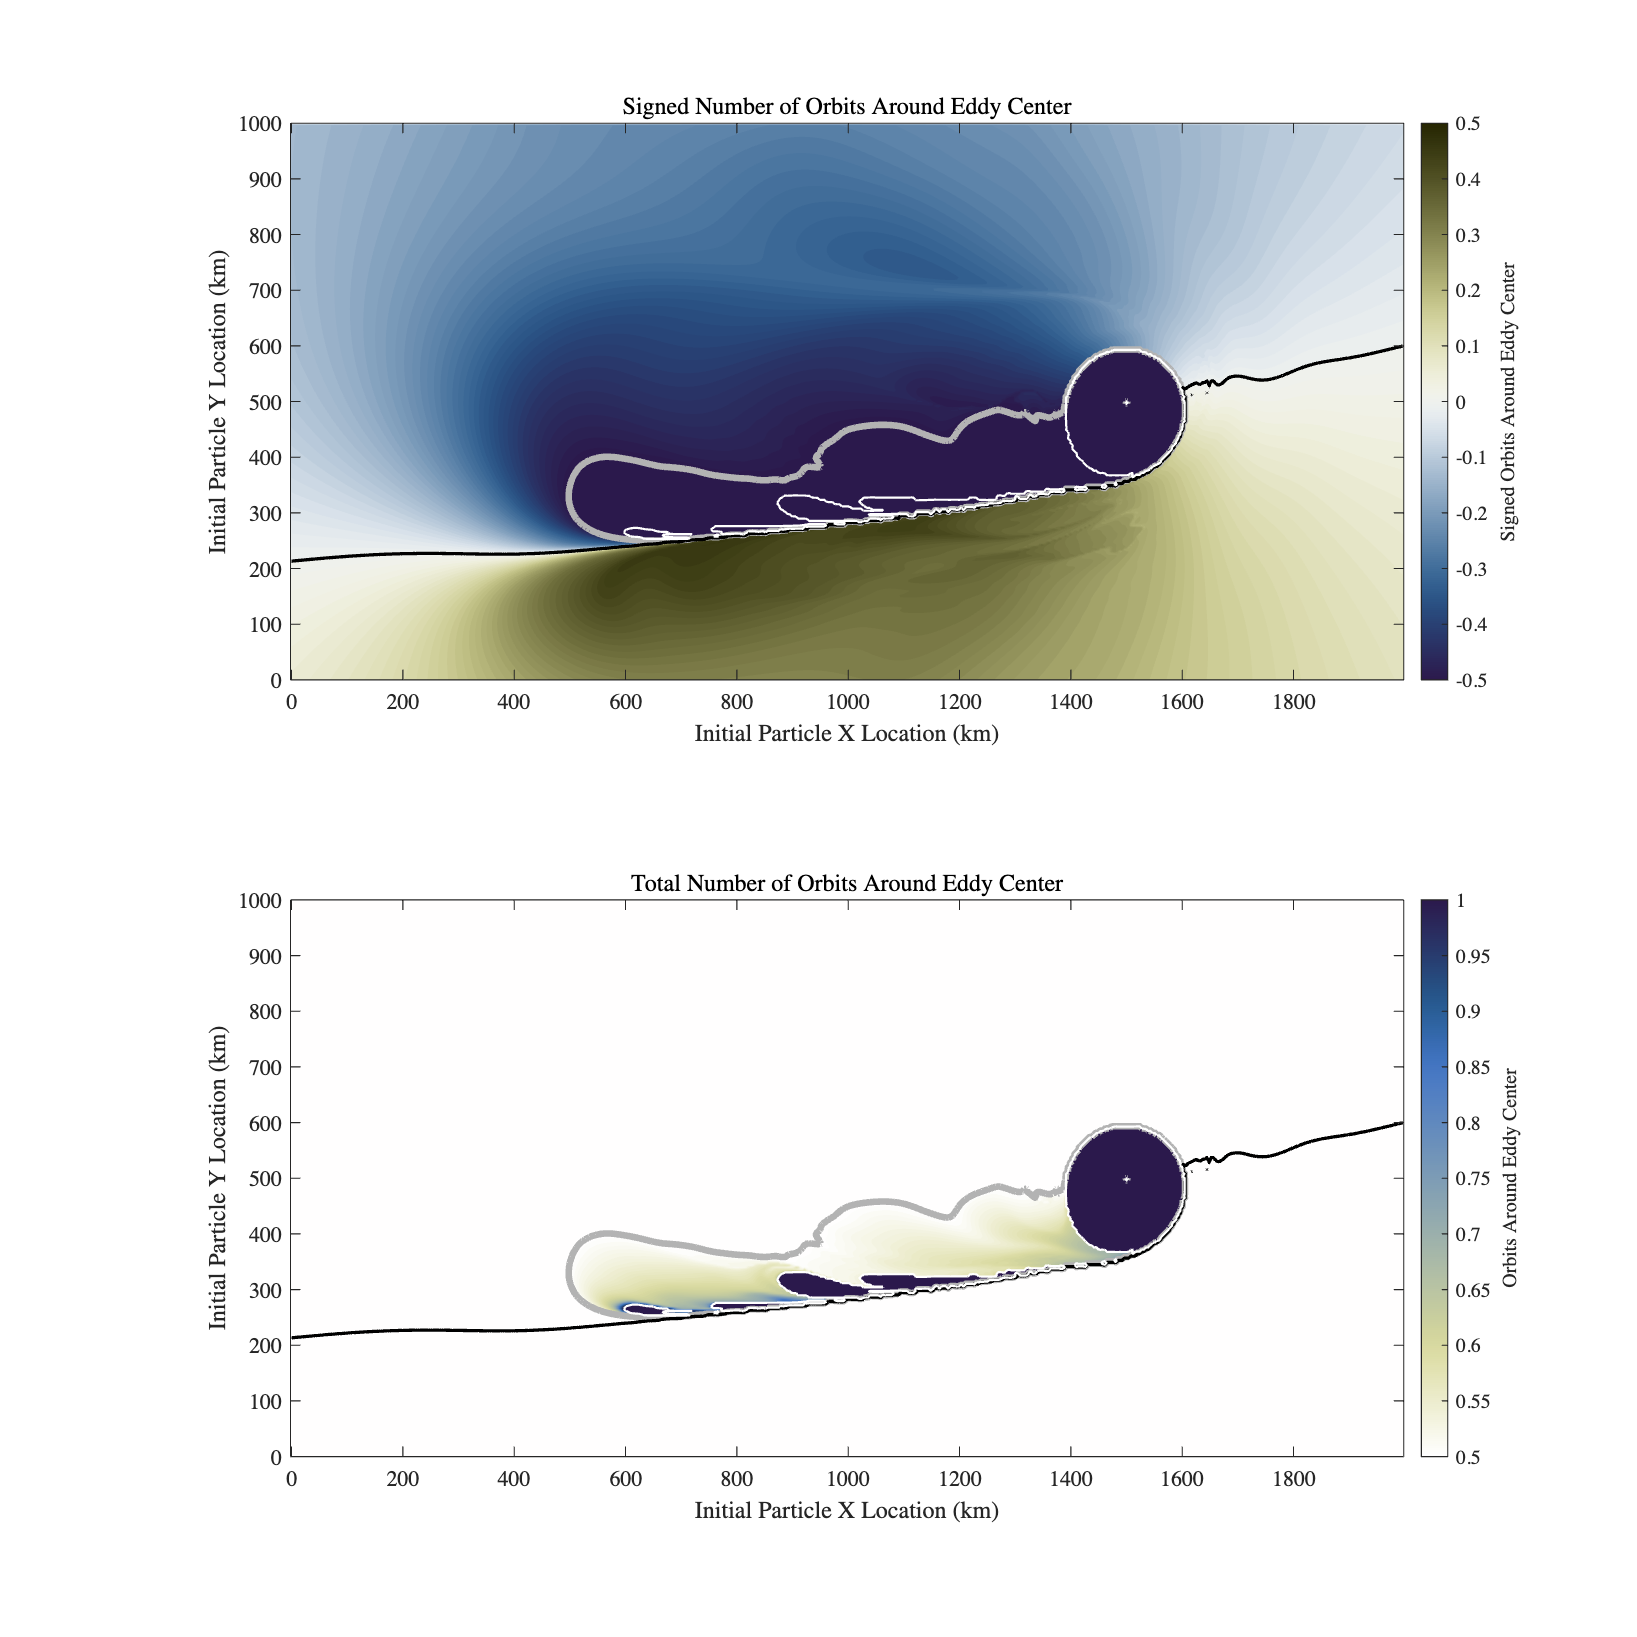

hf = figure();
hf.Position(3:4) = [1200,1200];
colormap(flipud(crameri('davos')))

tiledlayout(2,1);

ax=nexttile;
jpcolor(x,y,Norbits),hold on
contourf(x,y,Norbits,-1/2:0.01:1/2),nocontours, hold on, axis equal 
contour(x,y,Norbits,[-1/2 -1/2],color=[1 1 1]*0.7,linewidth=3)
contour(x,y,Norbits,[0 0],'k',linewidth=1.5)
contour(x,y,abs(Norbits),[1 1],'w',linewidth=1)
hc=colorbar('location','EastOutside');
hc.Label.String = "Signed Orbits Around Eddy Center";
title("Signed Number of Orbits Around Eddy Center")
clim([-1/2 1/2])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')
colormap(ax,crameri('broc'))

nexttile;
jpcolor(x,y,abs(Norbits)),hold on
contourf(x,y,abs(Norbits),1/2:0.005:1),nocontours, hold on, axis equal 
contour(x,y,Norbits,[-1/2 -1/2],color=[1 1 1]*0.7,linewidth=3)
contour(x,y,Norbits,[0 0],'k',linewidth=1.5)
contour(x,y,abs(Norbits),[1 1],'w',linewidth=1)
hc=colorbar('location','EastOutside');
hc.Label.String = "Orbits Around Eddy Center";
title("Total Number of Orbits Around Eddy Center")
clim([1/2 1])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')

This shows that there are four classes of particles: those which orbit in a cyclonic direction around the eddy center no more than 1/2 of an orbit, which is everything below the black line; those which orbit in an antiyclonic direction around the eddy center no more than 1/2 of an orbit, which is everything above the black line and outside of the gray contour; those which orbit anticyclonically between 1/2 and 1 orbit, which is the area enclosed by the gray contour but outside the white contour; and those which orbit anticyclonically greater than one orbit, which are those enclosed by the white contours, the dark blue region in the lower plot.

The third class of particles is interesting because it is semi-trapped: it is brought more than halfway around the eddy. This comes from a very predictible region. We can this phenonenon "bouncing."

Note also the sharp line dividing particles that will orbit cyclonically from those that will orbit anticyclonically.

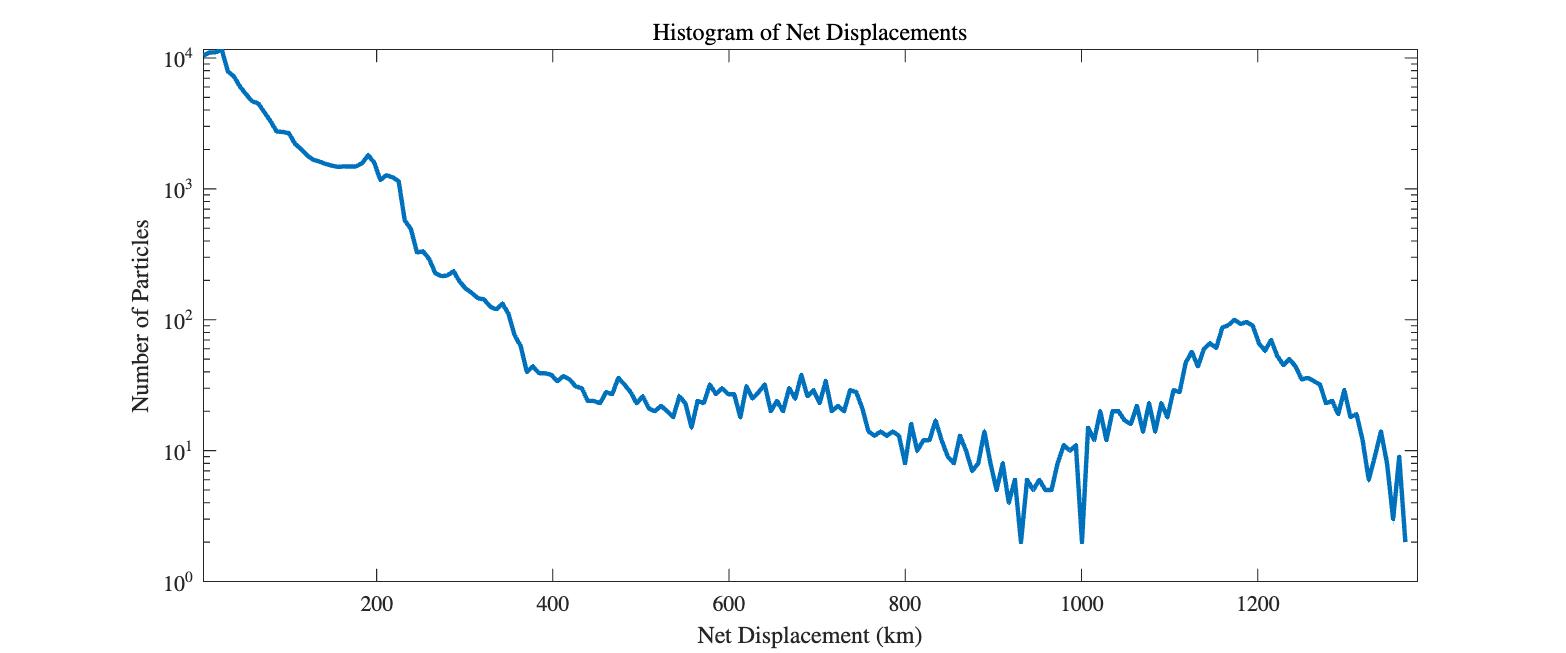

[n,values]=hist(d(:),200);

hf = figure();
hf.Position(3:4) = [1200,500];

plot(values,n,linewidth=2),ylog,axis tight
title("Histogram of Net Displacements")
xlabel('Net Displacement (km)')
ylabel('Number of Particles')

A few particles go a very long way!

Next we ask what fraction of the net transport is associated with trapping. 

%eastward motion associated with particles that are instantaneously trapped

uTrappedEastMoving = drifter_u;
uTrappedEastMoving(~isTrapped) = 0;
uTrappedEastMoving(drifter_u<0) = 0;
uTrappedEastMoving = reshape(mean(uTrappedEastMoving,1),length(x),length(y))';

uTrappedWestMoving = drifter_u;
uTrappedWestMoving(~isTrapped) = 0;
uTrappedWestMoving(drifter_u>0) = 0;
uTrappedWestMoving = reshape(mean(uTrappedWestMoving,1),length(x),length(y))';

%what is the transport? 
%sum(uTrappedEastMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %21 km/year, about 1/2 (of 41)
%sum(uTrappedWestMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %-42 km/year, all      (of 41)
%compare with -41.3.  Thus, 1/2 of the eastward transport is associated
%with fluid motions from particles that are instantaneously trapped, and all of
%the westward transport ... meaning, untrapped motions account for 1/2 of
%the eastward transport ... but, cancellations can be important here 

vTrappedNorthMoving = drifter_v;
vTrappedNorthMoving(~isTrapped) = 0;
vTrappedNorthMoving(drifter_v<0) = 0;
vTrappedNorthMoving = reshape(mean(vTrappedNorthMoving,1),length(x),length(y))';

vTrappedSouthMoving = drifter_v;
vTrappedSouthMoving(~isTrapped) = 0;
vTrappedSouthMoving(drifter_v>0) = 0;
vTrappedSouthMoving = reshape(mean(vTrappedSouthMoving,1),length(x),length(y))';

%what is the transport? 
%sum(vTrappedNorthMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %28.5 km/year 
%sum(vTrappedSouthMoving(:))*dA*(1/1000*24*3600*365)/(2e6) %-32 km/year
%the north/south displacements due to trapping actually add up to more than
%the total north/south transport (18 km/year), suggesting temporal cancellation
%---------------------------------------------------------------------------------
%another version, find transport due to particles that are *ever* trapped

isEverTrapped=reshape(mean(isTrapped,1)~=0,length(x),length(y))';
%sum(u_avg(movesEast&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.13 km/year (of 41)
%sum(u_avg(~movesEast&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-26 km/year (of 41)
%this means that essentially all of the eastward transport, and about 1/2 of the
%westward transport, is associated with particles that are *never* trapped
%sum(v_avg(movesNorth&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.37 km/year (of 18)
%sum(v_avg(~movesNorth&isEverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-4.7 km/year (of 18)
%again, essentially all of the northward transport, and about 3/4 of the
%southward transport, is associated with particles that are *never* trapped

isAlwaysTrapped=reshape(mean(isTrapped,1)==1,length(x),length(y))';
%sum(u_avg(movesEast&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.0 km/year (of 41)
%sum(u_avg(~movesEast&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-10 km/year (of 41)
%sum(v_avg(movesNorth&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0 km/year (of 18)
%sum(v_avg(~movesNorth&isAlwaysTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-1.8 km/year (of 18)

isNeverTrapped=reshape(mean(isTrapped,1)==0,length(x),length(y))';
%sum(u_avg(movesEast&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %41 km/year (of 41)
%sum(u_avg(~movesEast&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-15 km/year (of 41)
%sum(v_avg(movesNorth&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %17 km/year (of 18)
%sum(v_avg(~movesNorth&isNeverTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-13 km/year (of 18)

isSometimesTrapped=reshape(mean(isTrapped,1)~=0 & mean(isTrapped,1)~=1,length(x),length(y))';
%sum(u_avg(movesEast&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.12 km/year (of 41)
%sum(u_avg(~movesEast&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-15 km/year (of 41)
%sum(v_avg(movesNorth&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %0.37 km/year (of 18)
%sum(v_avg(~movesNorth&isSometimesTrapped),1)*dA*(1/1000*24*3600*365)/(2e6) %-2.8 km/year (of 18)

This analysis shows that motions outside of the trapping region, on the eddy periphery, play a major role in transport.  We can clarify this in the following way. 

isSometimesTrapped=reshape(mean(isTrapped,1)~=0 & mean(isTrapped,1)~=1,length(x),length(y))';
isAlwaysTrapped=reshape(mean(isTrapped,1)==1,length(x),length(y))';
isNeverTrapped=reshape(mean(isTrapped,1)==0,length(x),length(y))';
movesEast = (u_avg>0); 

%We only have four classes of particles
clear bool
bool{1}=(~movesEast)&isAlwaysTrapped;
bool{2}=(~movesEast)&isSometimesTrapped;
bool{3}=(~movesEast)&isNeverTrapped;
bool{4}=movesEast&isNeverTrapped;
bool{5}=movesEast&isSometimesTrapped; %can ignore this one

% length(find(bool{1})) %1159
% length(find(bool{2})) %3129
% length(find(bool{3})) %46055
% length(find(bool{4})) %80413
% length(find(bool{5})) %226
% length(bool1(:))-length(find(bool1|bool2|bool3|bool4|bool5))

% length(find(bool{1}))/length(bool{1}(:))*100  %0.88
% length(find(bool{2}))/length(bool{1}(:))*100  %2.46
% length(find(bool{3}))/length(bool{1}(:))*100  %35.14
% length(find(bool{4}))/length(bool{1}(:))*100  %61.35
% length(find(bool{5}))/length(bool{1}(:))*100  %0.17

meanu=zeros(size(drifter_u,1),5);
meanv=zeros(size(drifter_v,1),5);
for k=1:size(meanu,1)
    uk = drifter_u(k,:);
    %uk = reshape(uk,length(y),length(x));
    %uk = reshape(uk,length(x),length(y));
    vk = drifter_v(k,:);
    %vk = reshape(vk,length(y),length(x));
    %vk = reshape(vk,length(x),length(y));

    for i=1:5    
         %Note the right way to apply the index to avoid a transpose error is 
         %vcolon(bool{i}') not bool{i}(:)
         meanu(k,i)=mean(uk(vcolon(bool{i}')));
         meanv(k,i)=mean(vk(vcolon(bool{i}')));
    end
end

%find cumulative mean 
cummeanu=meanu;
cummeanv=meanv;
for k=1:size(meanu,1)
    cummeanu(k,:)=mean(meanu(1:k,:),1);
    cummeanv(k,:)=mean(meanv(1:k,:),1);
end

%now weight by area
weight=meanu;
for i=1:5
    weight(:,i) = length(find(bool{i}))/length(bool{1}(:)) + 0*weight(:,i);
end

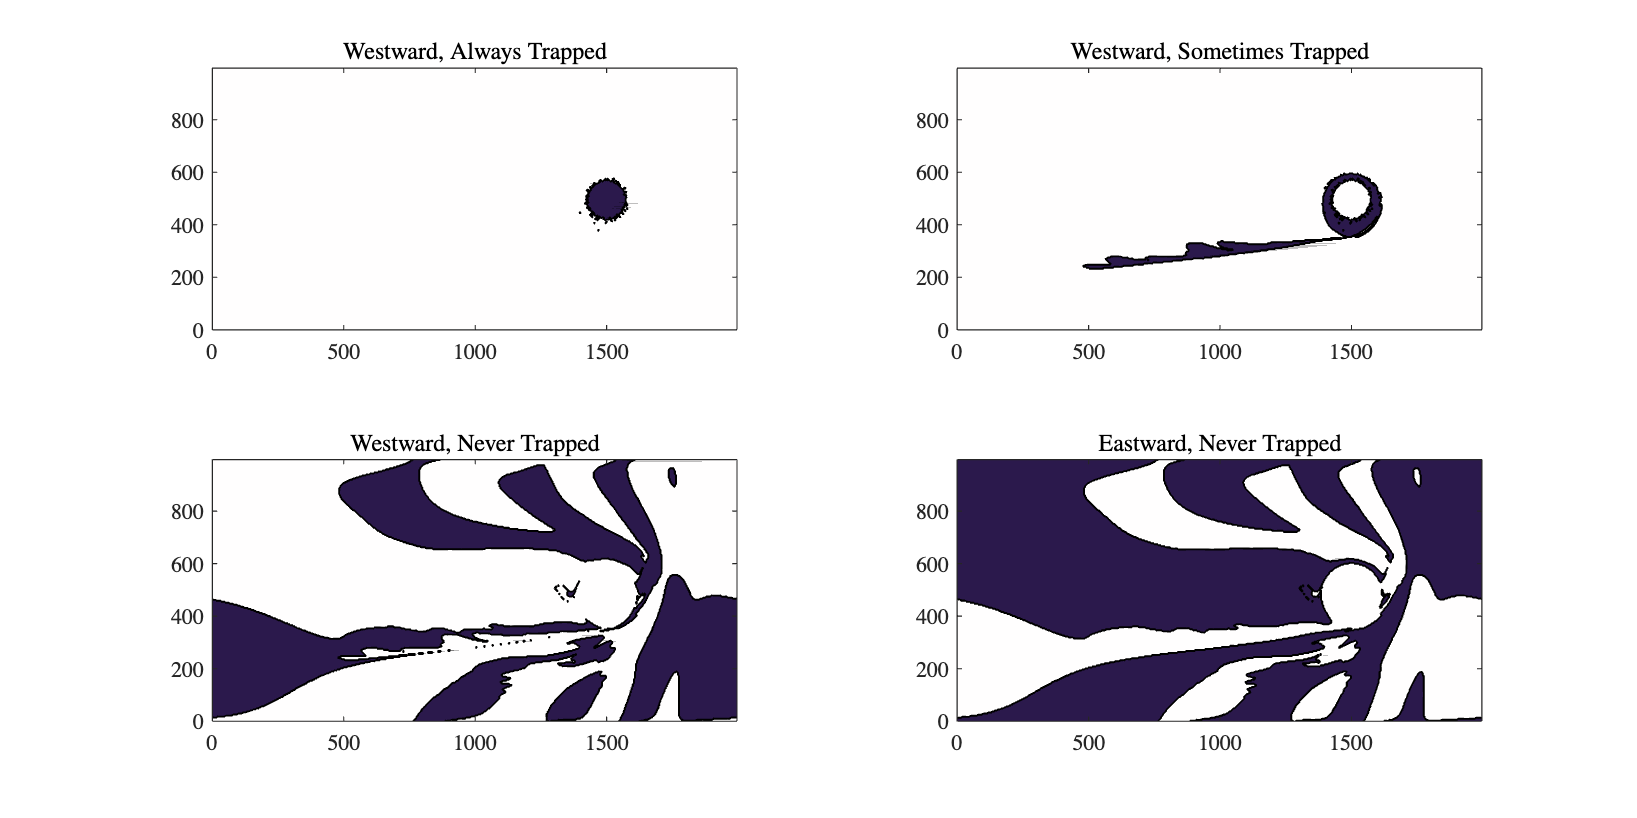

hf = figure();
hf.Position(3:4) = [1200,600];
colormap(flipud(crameri('davos')))

tiledlayout(2,2);

nexttile
contourf(x,y,bool{1});hold on, axis equal, axis tight
title("Westward, Always Trapped")

nexttile
contourf(x,y,bool{2});hold on, axis equal, axis tight
title("Westward, Sometimes Trapped")

nexttile
contourf(x,y,bool{3});hold on, axis equal, axis tight
title("Westward, Never Trapped")

nexttile
contourf(x,y,bool{4});hold on, axis equal, axis tight
title("Eastward, Never Trapped")

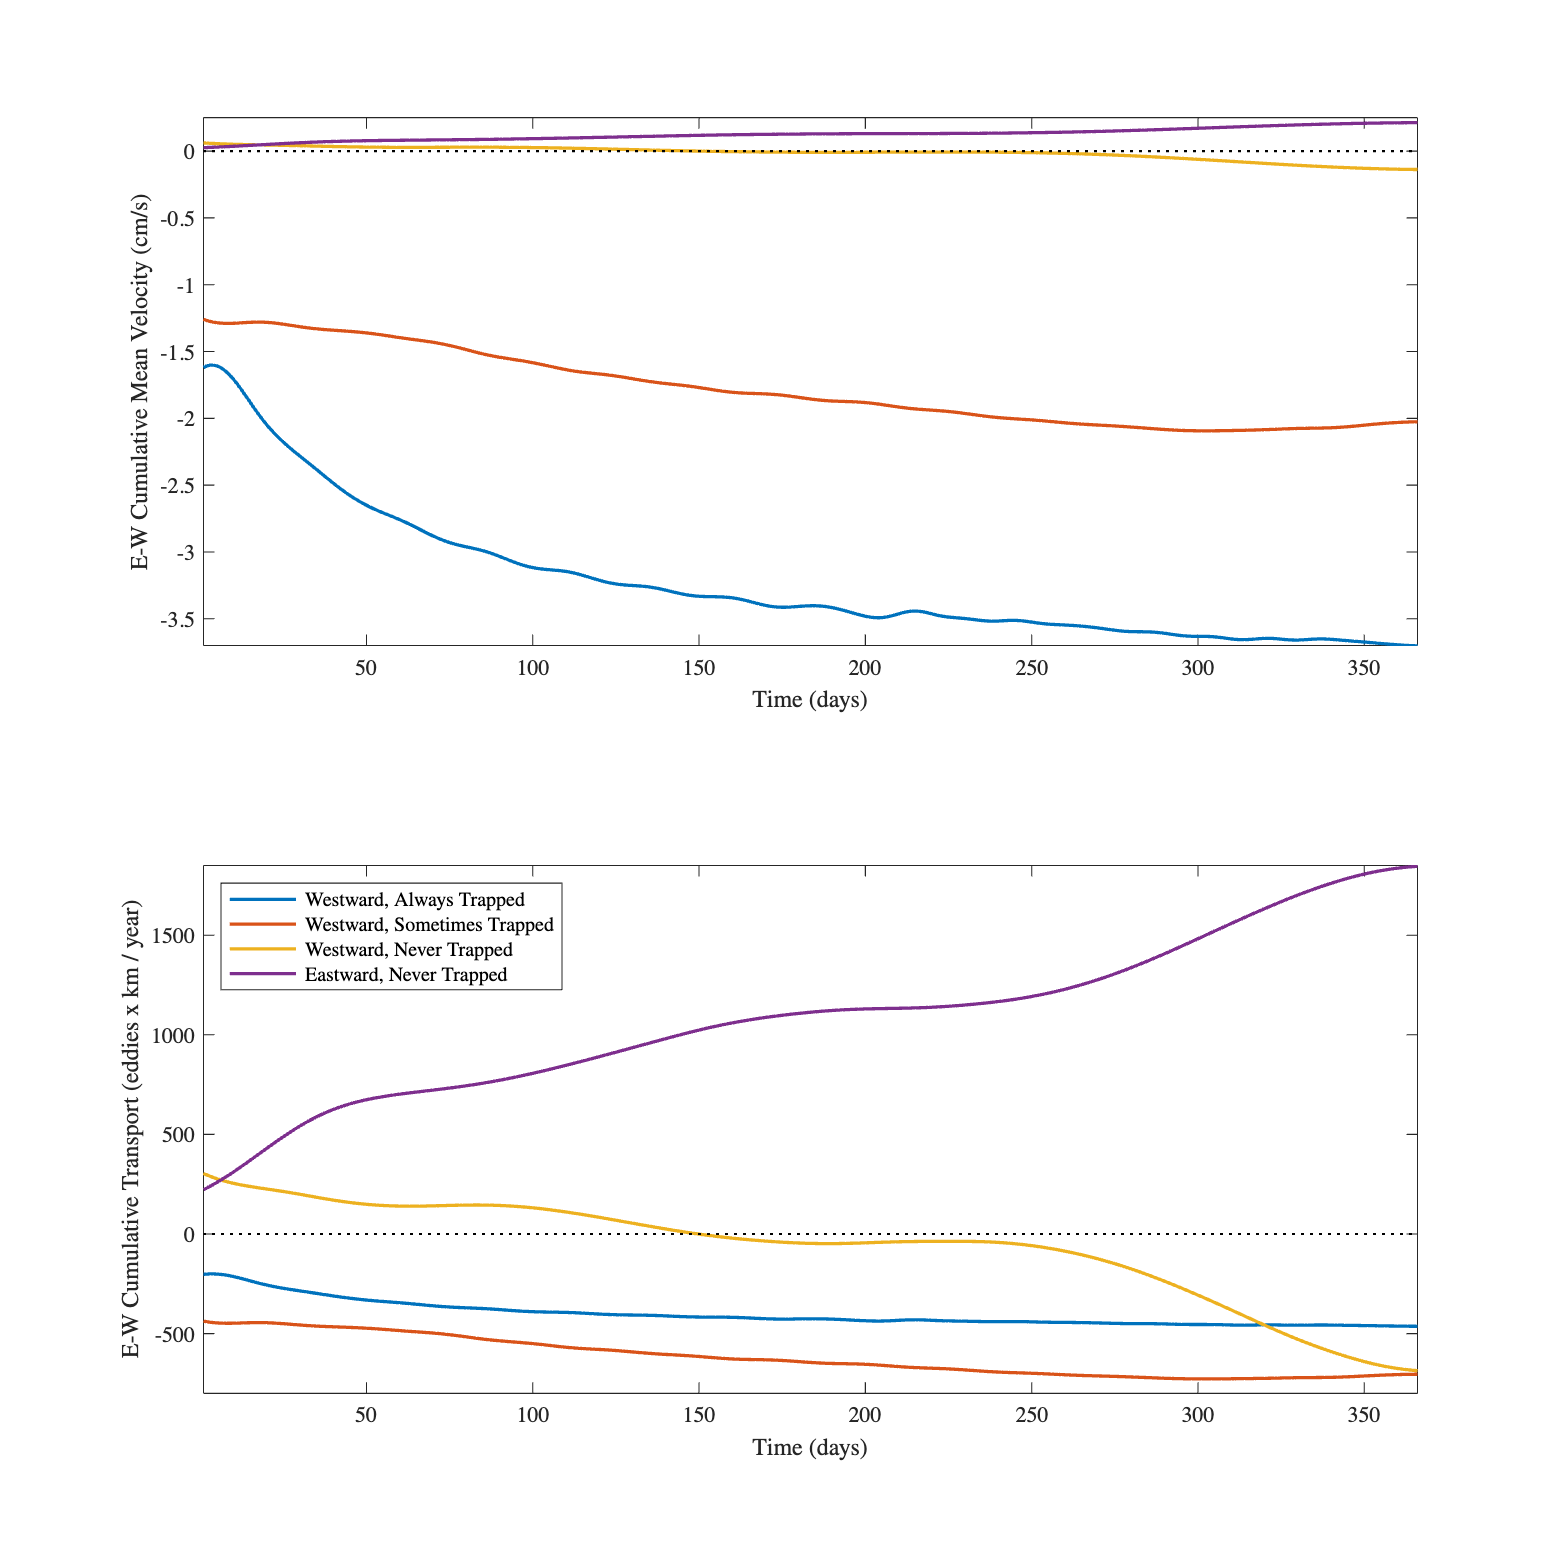

hf = figure();
hf.Position(3:4) = [1200,1200];

tiledlayout(2,1);

nexttile;
plot(cummeanu(:,1:4),linewidth=1.5);axis tight,hlines(0,'k:')
ylabel('E-W Cumulative Mean Velocity (cm/s)')
xlabel("Time (days)")
ylim([-3.7 0.25])

% nexttile;
% h=plot(100*cummeanv(:,1:4),linewidth=1.5);,axis tight,hlines(0,'k:')
% ylabel('N-S Cumulative Mean Velocity (cm/s)')
% xlabel("Time (days)")
% ylim([-3.7 0.25])

factor = 512*256*dA*(1/1000/100*24*3600*365)/Eo;

nexttile;
h=plot(weight(:,1:4).*cummeanu(:,1:4)*factor,linewidth=1.5);axis tight,hlines(0,'k:')
ylabel('E-W Cumulative Transport (eddies x km / year)')
xlabel("Time (days)")
ylim([-800 1850])


% nexttile;
% plot(weight(:,1:4).*cummeanv(:,1:4)*factor,linewidth=1.5),axis tight,hlines(0,'k:')
% ylabel('N-S Cumulative Transport (eddies x km / year)')
% xlabel("Time (days)")
% ylim([-800 1850])
legend(h(1:4),'Westward, Always Trapped','Westward, Sometimes Trapped',...
    'Westward, Never Trapped','Eastward, Never Trapped','location','northwest')

This plot shows that if we only count the fluid trapping, we are only accounting for about 25% of the westward transport. 

Before continuing, let's look at entraiment statistics 

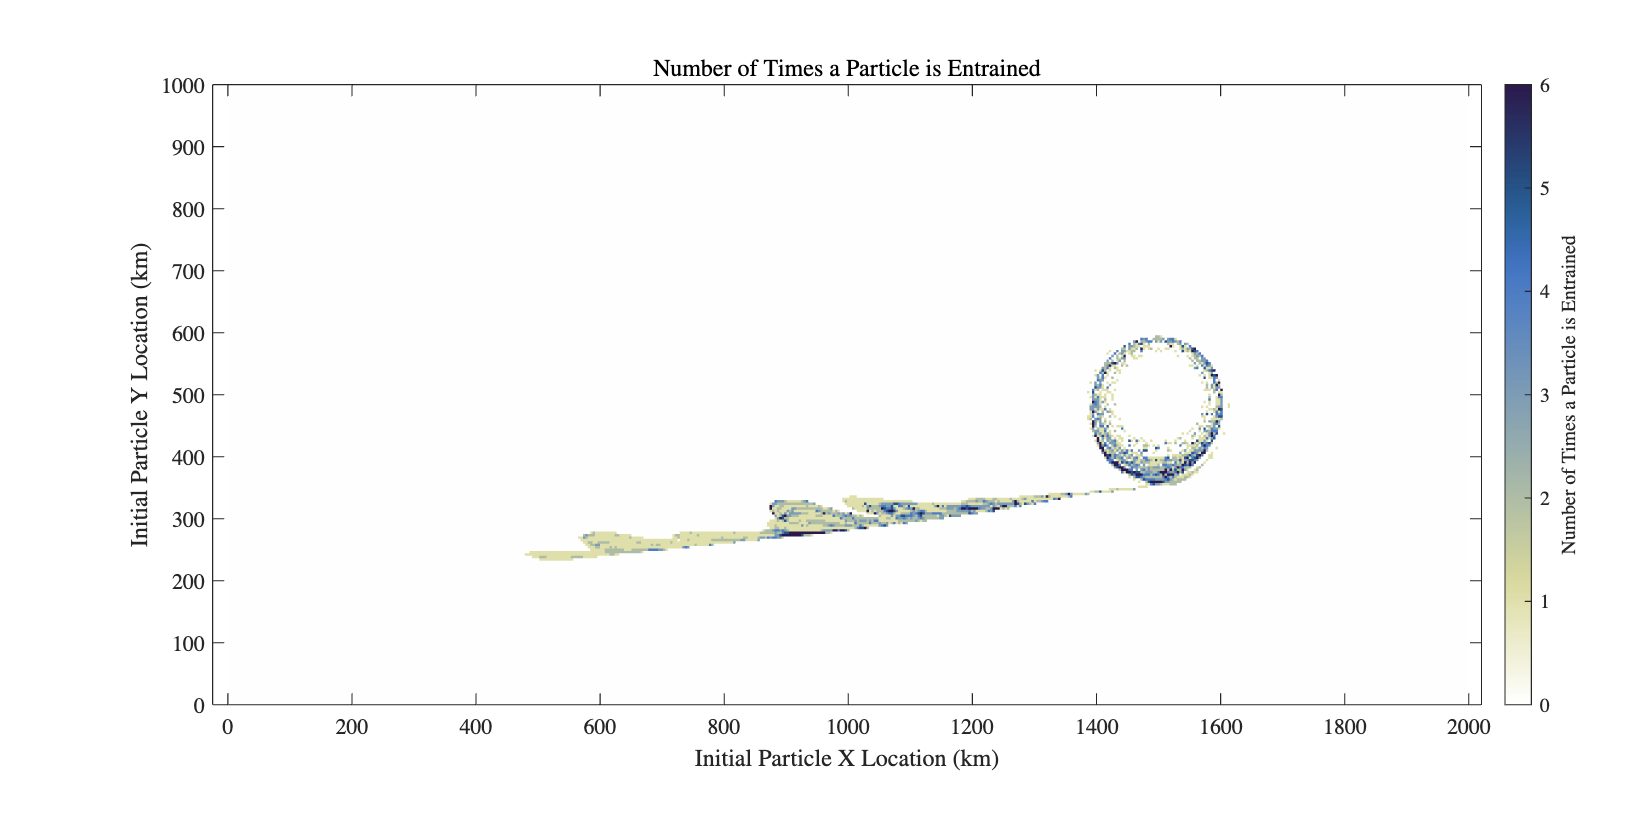

%is fluid repeatedly entrained and detrained?  Yes,actually  ... show thes
Nentrainments = reshape(sum(diff(isTrapped,1)>0,1),length(x),length(y))';
%length(find(sum(diff(isTrapped,1)>0,1)==1))%1280
%length(find(sum(diff(isTrapped,1)>0,1)==2))%617
%length(find(sum(diff(isTrapped,1)>0,1)==3))%379
%length(find(sum(diff(isTrapped,1)>0,1)==4))%211
%length(find(sum(diff(isTrapped,1)>0,1)==5))%100
%should plot this 

hf = figure();
hf.Position(3:4) = [1200,600];
colormap(flipud(crameri('davos')))

tiledlayout(1,1)

nexttile
jpcolor(x,y,Nentrainments),hold on,axis equal
%contourf(x,y,Norbits,-1/2:0.01:1/2),nocontours, hold on, axis equal 
%contour(x,y,Norbits,[-1/2 -1/2],color=[1 1 1]*0.7,linewidth=3)
%contour(x,y,Norbits,[0 0],'k',linewidth=1.5)
%contour(x,y,abs(Norbits),[1 1],'w',linewidth=1)
hc=colorbar('location','EastOutside');
hc.Label.String = "Number of Times a Particle is Entrained";
title("Number of Times a Particle is Entrained")
%clim([-1/2 1/2])
xlabel('Initial Particle X Location (km)')
ylabel('Initial Particle Y Location (km)')

Let's try another decomposition which is more mechanistic.

isInitiallyTrapped=reshape(isTrapped(1,:),length(x),length(y))';
isFinallyTrapped=reshape(isTrapped(end,:),length(x),length(y))';
isAlwaysTrapped=reshape(mean(isTrapped,1)==1,length(x),length(y))';
isEverTrapped=reshape(mean(isTrapped,1)~=0,length(x),length(y))';
isEntrained=reshape(sum(diff(isTrapped,1)>0,1)>0,length(x),length(y))';
isEntrainedOnlyOnce=reshape(sum(diff(isTrapped,1)>0,1)==1,length(x),length(y))';

clear bool
bool{1}=isInitiallyTrapped&isAlwaysTrapped;%1159 <1%
bool{2}=isInitiallyTrapped&~isAlwaysTrapped;%1760
bool{3}=~isInitiallyTrapped&isEverTrapped;%1685 1.2%
bool{4}=~isInitiallyTrapped&~isEverTrapped;%126468  96%

L=zeros(length(bool),1);
for i=1:length(bool)
    L(i)=length(find(bool{i}));
end

L./sum(L)*100

ans =     0.8842
    1.3428
    1.2856
   96.4874



meanu=zeros(size(drifter_u,1),length(bool));
meanv=zeros(size(drifter_v,1),length(bool));
for k=1:size(meanu,1)
    uk = drifter_u(k,:);
    vk = drifter_v(k,:);

    for i=1:length(bool)
         %Note the right way to apply the index to avoid a transpose error is 
         %vcolon(bool{i}') not bool{i}(:)
         meanu(k,i)=mean(uk(vcolon(bool{i}')));
         meanv(k,i)=mean(vk(vcolon(bool{i}')));
    end
end

%find cumulative mean 
cummeanu=meanu;
cummeanv=meanv;
for k=1:size(meanu,1)
    cummeanu(k,:)=mean(meanu(1:k,:),1);
    cummeanv(k,:)=mean(meanv(1:k,:),1);
end

%now weight by area
weight=meanu;
for i=1:length(bool)
    weight(:,i) = length(find(bool{i}))/length(bool{1}(:)) + 0*weight(:,i);
end

%compute final positions
dx = x(2)-x(1);
xbins = x(1)-dx/2:dx:x(end)+dx/2;
ybins = y(1)-dx/2:dx:y(end)+dx/2;
xf = reshape(drifter_x(end,:),length(x),length(y))';
yf = reshape(drifter_y(end,:),length(x),length(y))';

for i=1:length(bool)
    [boolf{i},xmid,ymid] = twodstats(xf,yf,bool{i}+0,xbins,ybins);
end
%aresame(x,xmid),aresame(y,ymid)

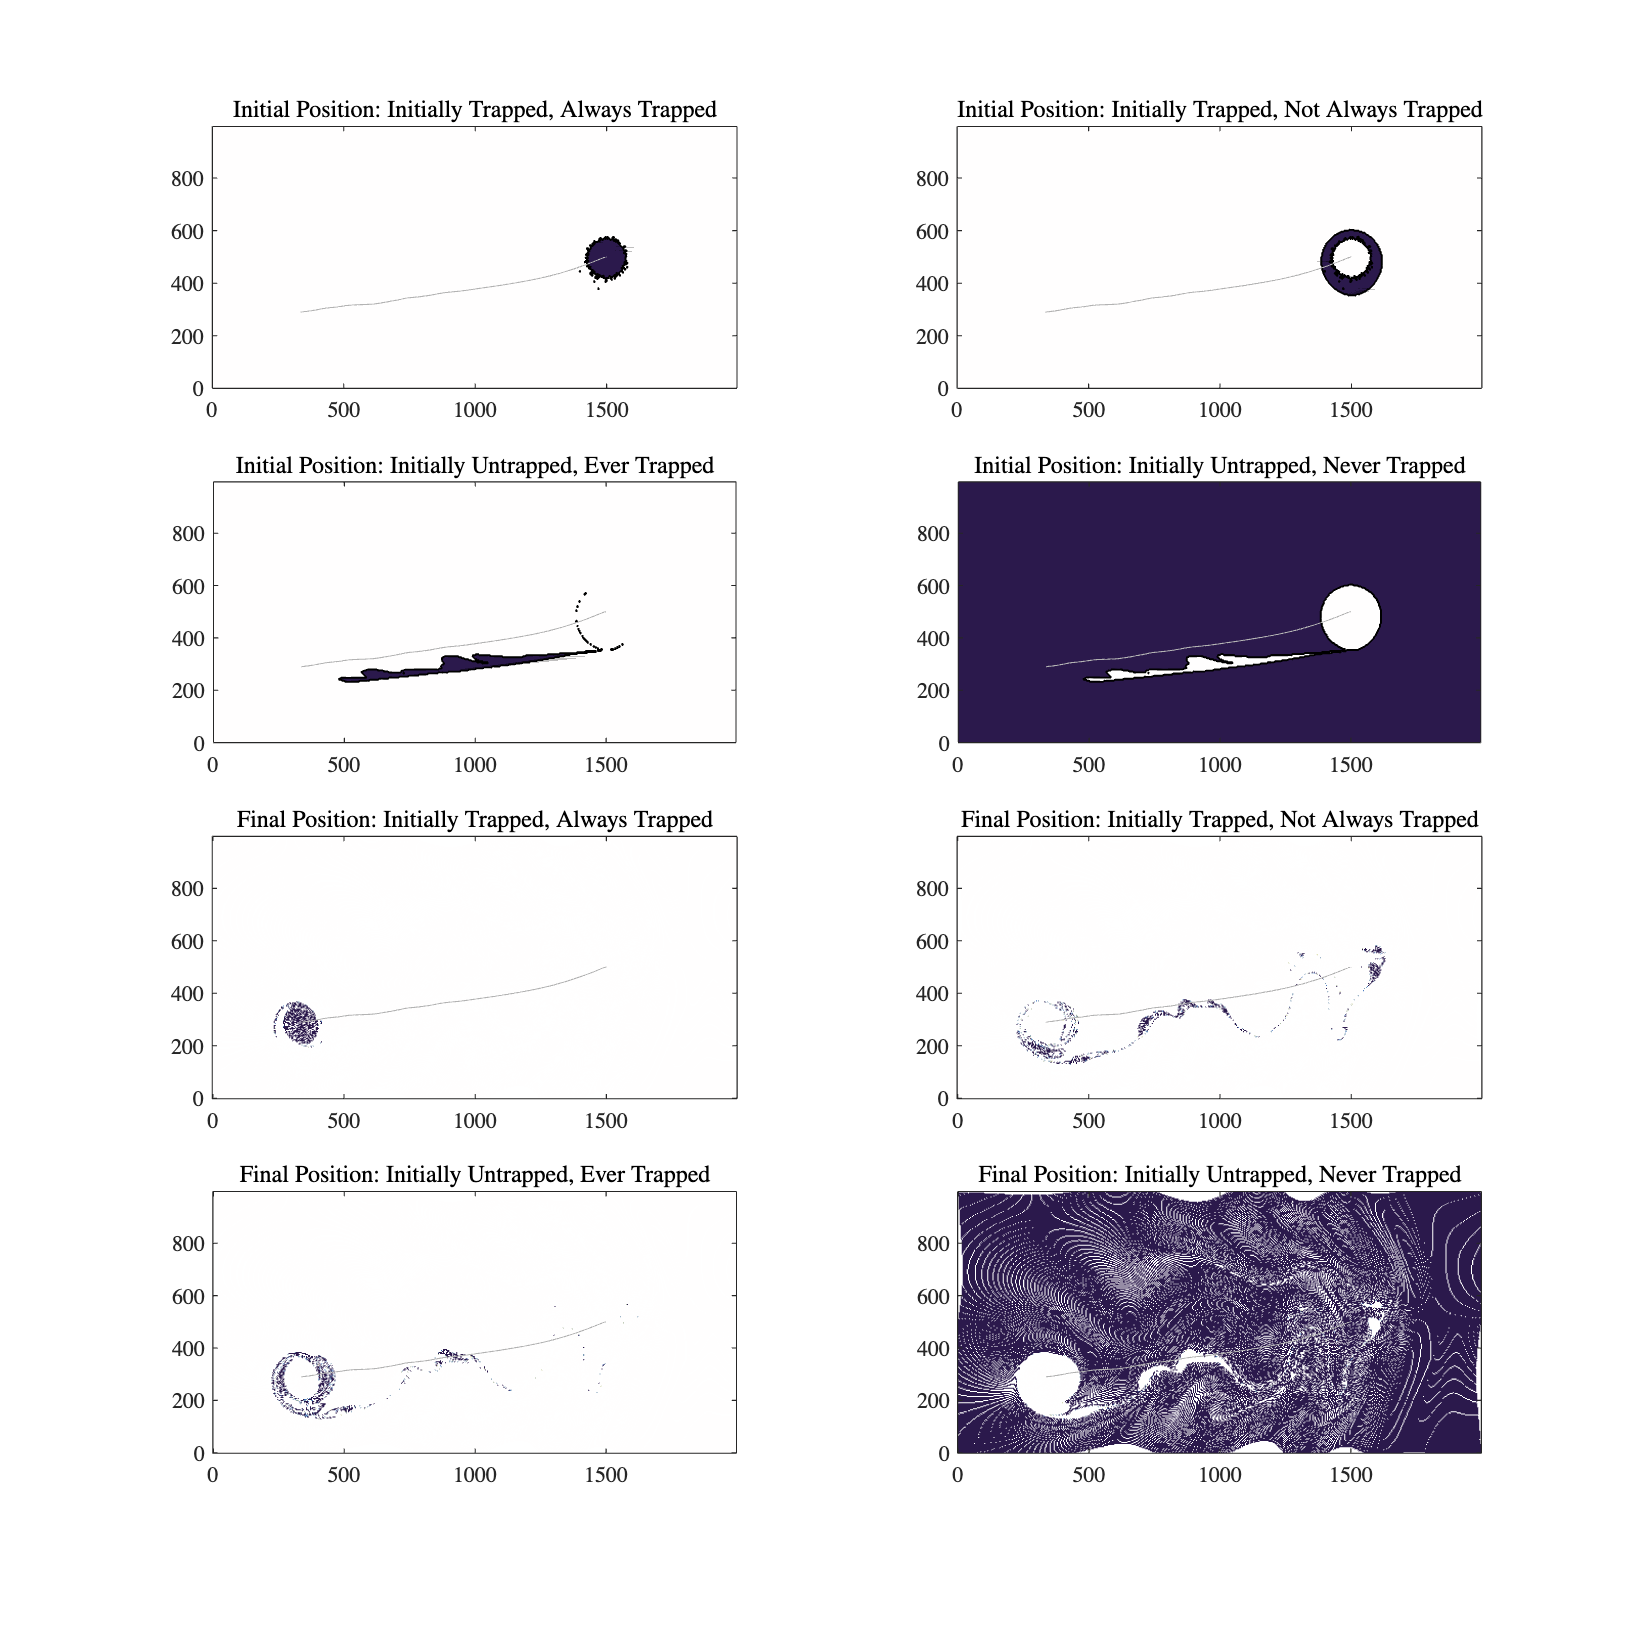

hf = figure();
hf.Position(3:4) = [1200,1200];
colormap(flipud(crameri('davos')))

tiledlayout(4,2);

nexttile
contourf(x,y,bool{1});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Initially Trapped, Always Trapped")

nexttile
contourf(x,y,bool{2});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Initially Trapped, Not Always Trapped")

nexttile
contourf(x,y,bool{3});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Initially Untrapped, Ever Trapped")

nexttile
contourf(x,y,bool{4});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Initially Untrapped, Never Trapped")

nexttile
jpcolor(x,y,boolf{1});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Initially Trapped, Always Trapped")

nexttile
jpcolor(x,y,boolf{2});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Initially Trapped, Not Always Trapped")

nexttile
jpcolor(x,y,boolf{3});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Initially Untrapped, Ever Trapped")

nexttile
jpcolor(x,y,boolf{4});hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Initially Untrapped, Never Trapped")

Note that the final distributions of initally trapped but not always trapped particles, and initially untrapped but ever trapped particles, are very similar. This supports the idea of a core and a ring having different behaviors, with the ring being fluid particles that are sometimes but not always trapped. 

Where does the bounced fluid end up?

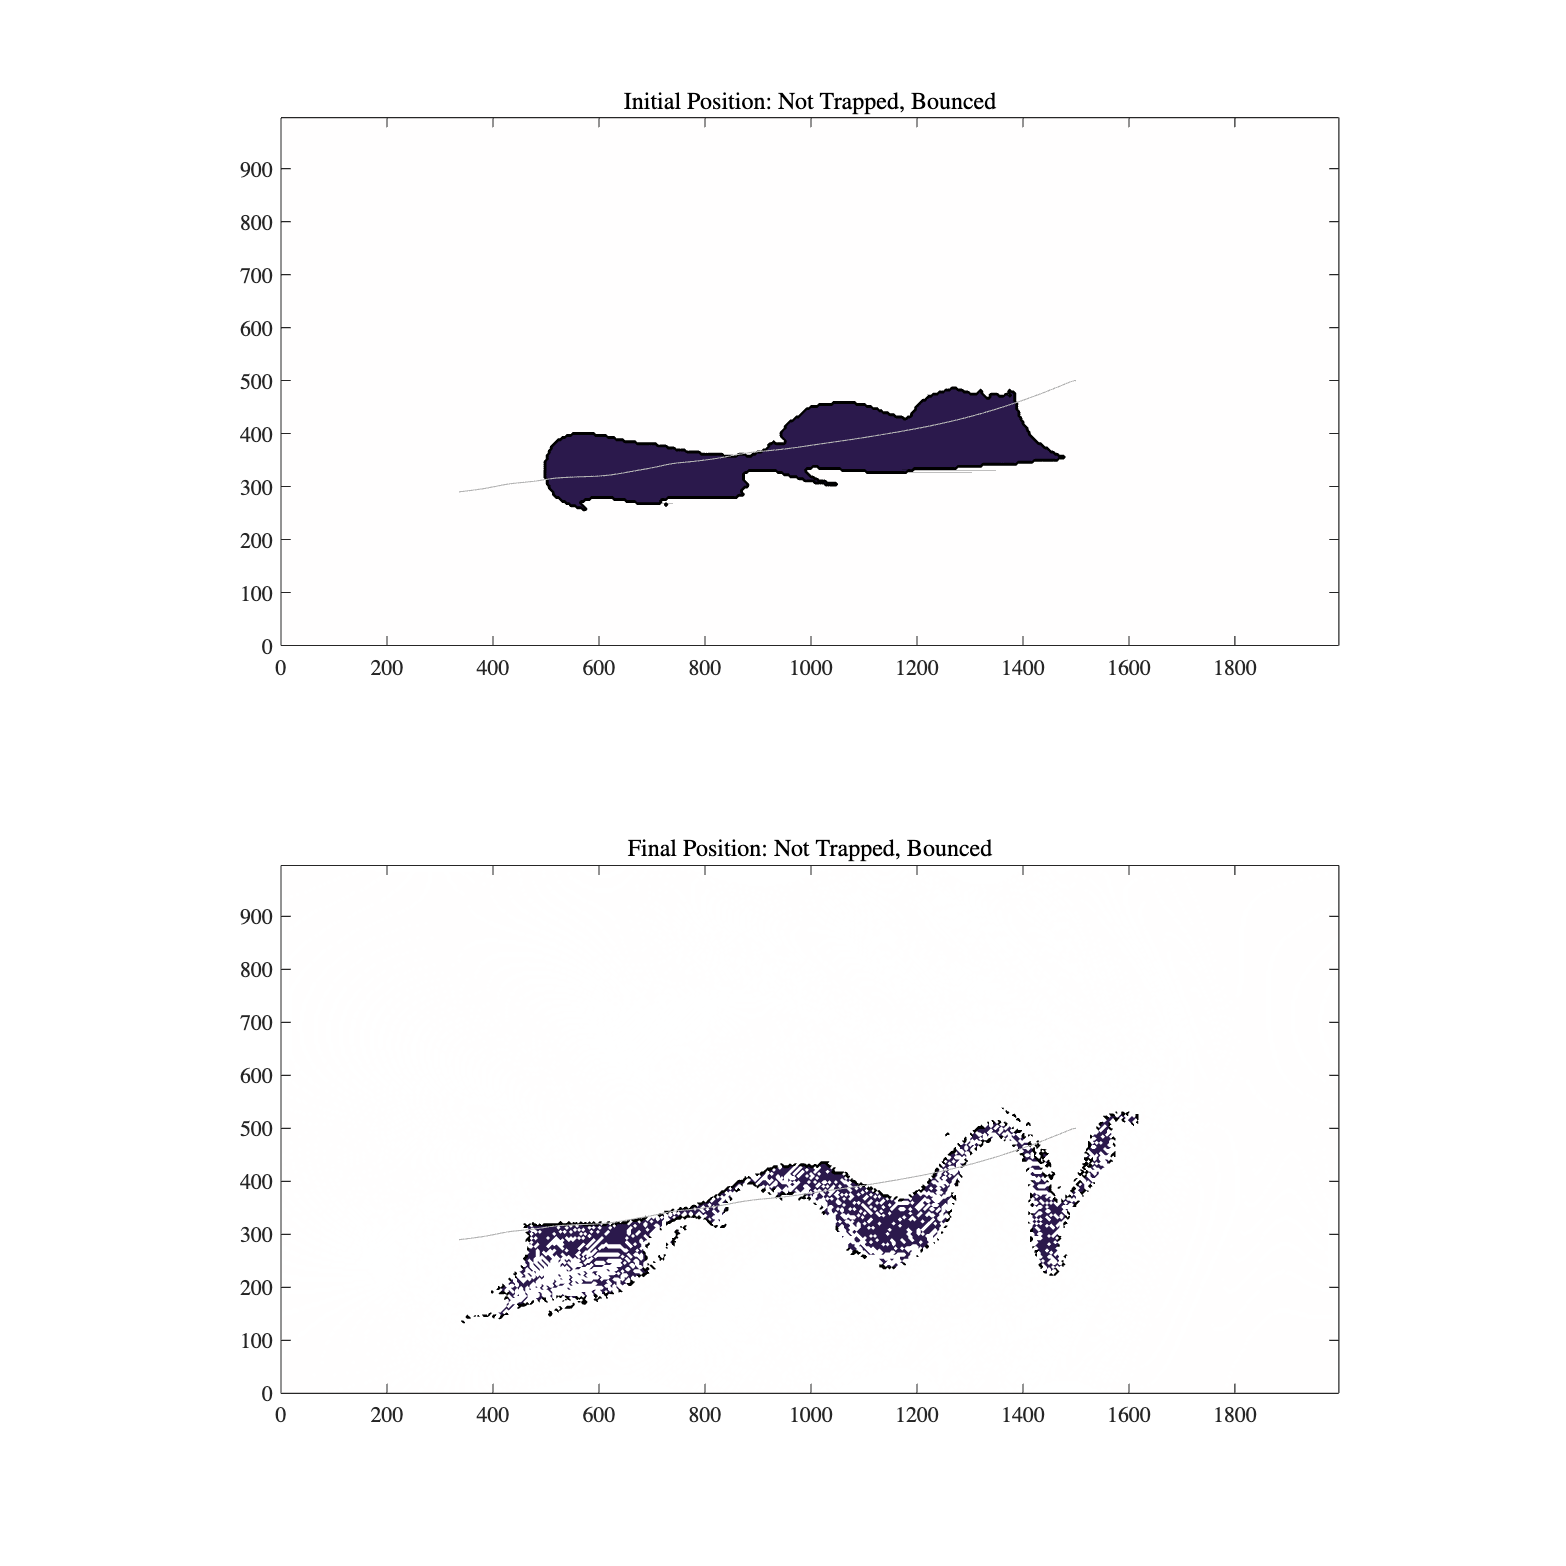

boold = ~isInitiallyTrapped&~isEntrained&abs(Norbits)>1/2;%6583, 5%!!
%compute final positions
dx = x(2)-x(1);
xbins = x(1)-dx/2:dx:x(end)+dx/2;
ybins = y(1)-dx/2:dx:y(end)+dx/2;
xf = reshape(drifter_x(end,:),length(x),length(y))';
yf = reshape(drifter_y(end,:),length(x),length(y))';

booldf = twodstats(xf,yf,boold+0,xbins,ybins);

hf = figure();
hf.Position(3:4) = [1200,1200];
colormap(flipud(crameri('davos')))

tiledlayout(2,1);

nexttile
contourf(x,y,boold);hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Initial Position: Not Trapped, Bounced")

nexttile
contourf(x,y,booldf);hold on, axis equal, axis tight,plot(xo,yo,color=[1 1 1]*0.7)
title("Final Position: Not Trapped, Bounced")

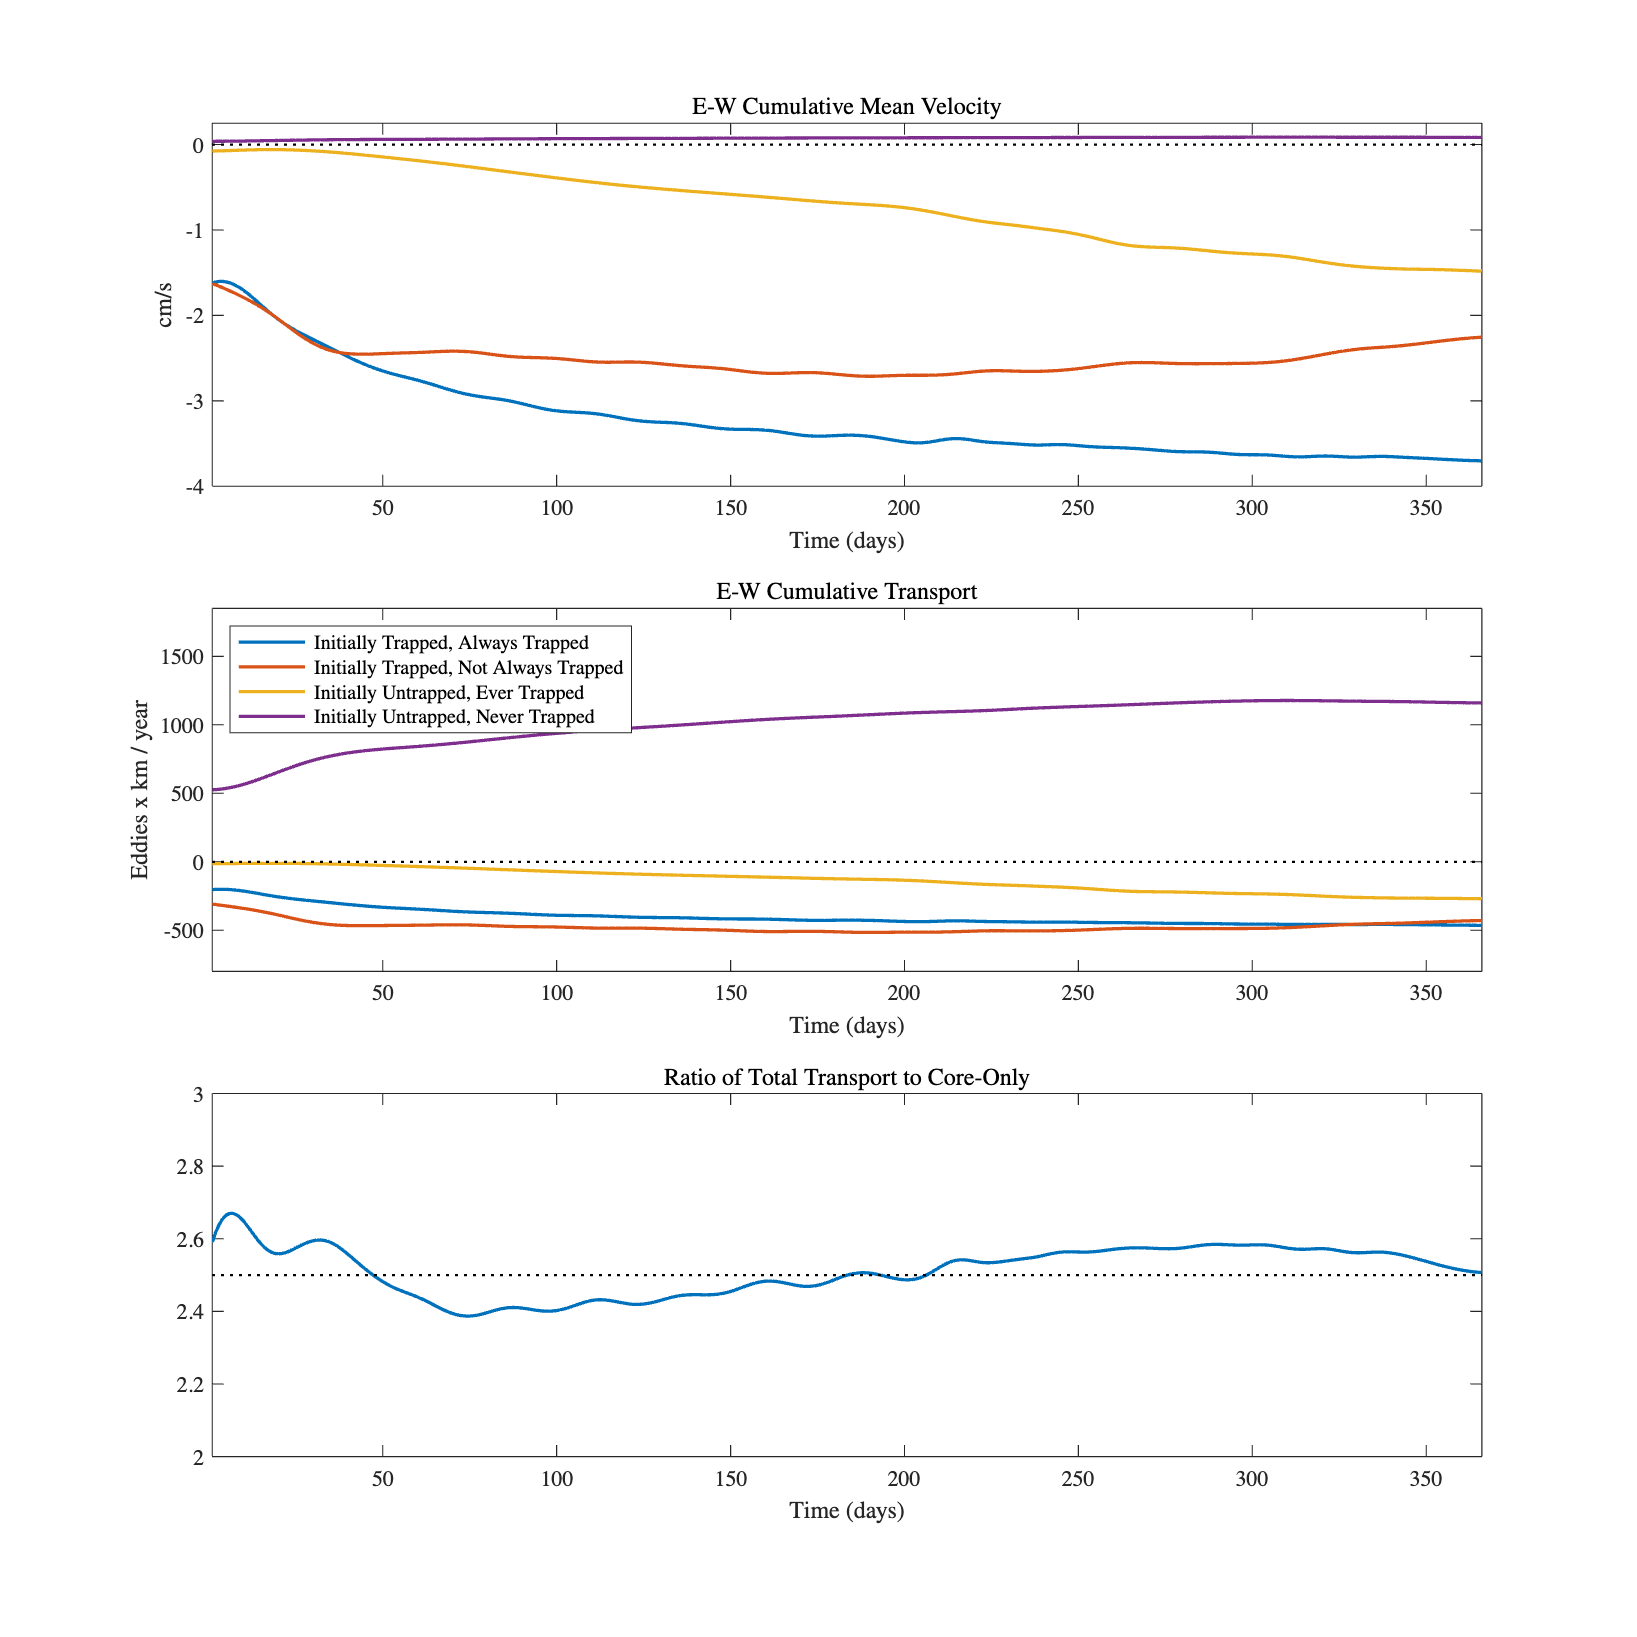

hf = figure();
hf.Position(3:4) = [1200,1200];

tiledlayout(3,1);

nexttile;
plot(cummeanu,linewidth=1.5);axis tight,hlines(0,'k:')
title('E-W Cumulative Mean Velocity')
ylabel('cm/s')
xlabel("Time (days)")
ylim([-4 0.25])

factor = 512*256*dA*(1/1000/100*24*3600*365)/Eo;

nexttile;
h=plot(weight.*cummeanu*factor,linewidth=1.5);axis tight,hlines(0,'k:'),hold on
%plot(weight(:,2).*cummeanu(:,2)*factor+weight(:,3).*cummeanu(:,3)*factor,linewidth=1.5);
title('E-W Cumulative Transport')
ylabel('Eddies x km / year')
xlabel("Time (days)")
ylim([-800 1850])

legend(h,'Initially Trapped, Always Trapped','Initially Trapped, Not Always Trapped',...
    'Initially Untrapped, Ever Trapped','Initially Untrapped, Never Trapped',...
    'location','northwest')

nexttile;
ratio = 1 + (weight(:,2).*cummeanu(:,2) + weight(:,3).*cummeanu(:,3))./(weight(:,1).*cummeanu(:,1));
h=plot(ratio,linewidth=1.5);axis tight
hlines(2.5,'k:')
title('Ratio of Total Transport to Core-Only')
xlabel("Time (days)")
ylim([2 3])

%compute some statistics centered on the eddy
bins=-250:2.5:250;
[mu,xmid,ymid,numz,stdu]=twodstats(drifter_x-xo,drifter_y-yo,drifter_u,bins,bins);
[mv,xmid,ymid,numz,stdv]=twodstats(drifter_x-xo,drifter_y-yo,drifter_v,bins,bins);
[mt,xmid,ymid,numz,stdt]=twodstats(drifter_x-xo,drifter_y-yo,isTrapped,bins,bins);

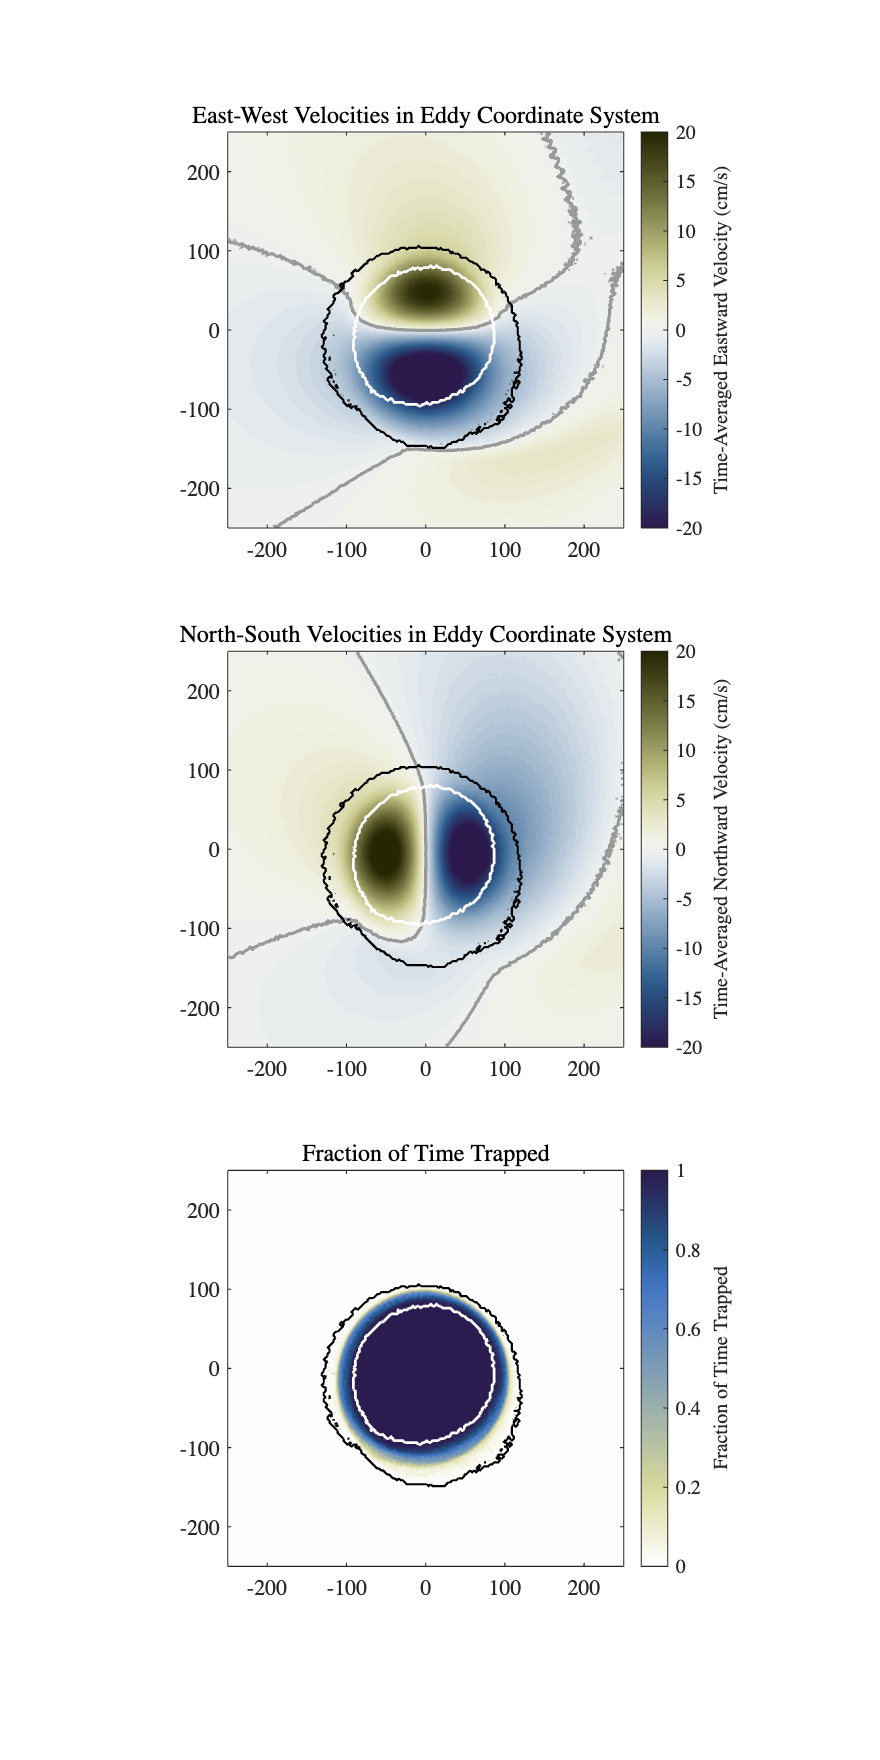

hf = figure();
hf.Position(3:4) = [1200,2400];
colormap(crameri('broc'))

tiledlayout(3,1);

nexttile;
contourf(xmid,ymid,mu,100),nocontours, hold on,axis equal
contour(xmid,ymid,mu,[0 0],linewidth=1.5,color=[1 1 1]*0.6)
contour(xmid,ymid,mt,[1 1],'w',linewidth=1.25)
contour(xmid,ymid,mt,[0 0]+1e-6,'k',linewidth=1)
clim([-.2 .2]*100),axis([-1 1 -1 1]*250)
%cellplot(xpc(1:14:end),ypc(1:14:end),'0.25C')
title('East-West Velocities in Eddy Coordinate System')
hc=colorbar('location','EastOutside');
hc.Label.String = "Time-Averaged Eastward Velocity (cm/s)";

nexttile;
contourf(xmid,ymid,mv,100),nocontours, hold on,axis equal
contour(xmid,ymid,mv,[0 0],linewidth=1.5,color=[1 1 1]*0.6)
contour(xmid,ymid,mt,[1 1],'w',linewidth=1.25)
contour(xmid,ymid,mt,[0 0]+1e-6,'k',linewidth=1)
clim([-.2 .2]*100),axis([-1 1 -1 1]*250)
%cellplot(xpc(1:14:end),ypc(1:14:end),'0.25C')
title('North-South Velocities in Eddy Coordinate System')
hc=colorbar('location','EastOutside');
hc.Label.String = "Time-Averaged Northward Velocity (cm/s)";

ax=nexttile;
contourf(xmid,ymid,mt,100),nocontours, hold on,axis equal
contour(xmid,ymid,mt,[1 1],'w',linewidth=1.25)
contour(xmid,ymid,mt,[0 0]+1e-6,'k',linewidth=1)
clim([0 1]),axis([-1 1 -1 1]*250)
colormap(ax,flipud(crameri('davos')))
%cellplot(xpc(1:14:end),ypc(1:14:end),'0.25D')
title('Fraction of Time Trapped')
hc=colorbar('location','EastOutside');
hc.Label.String = "Fraction of Time Trapped";

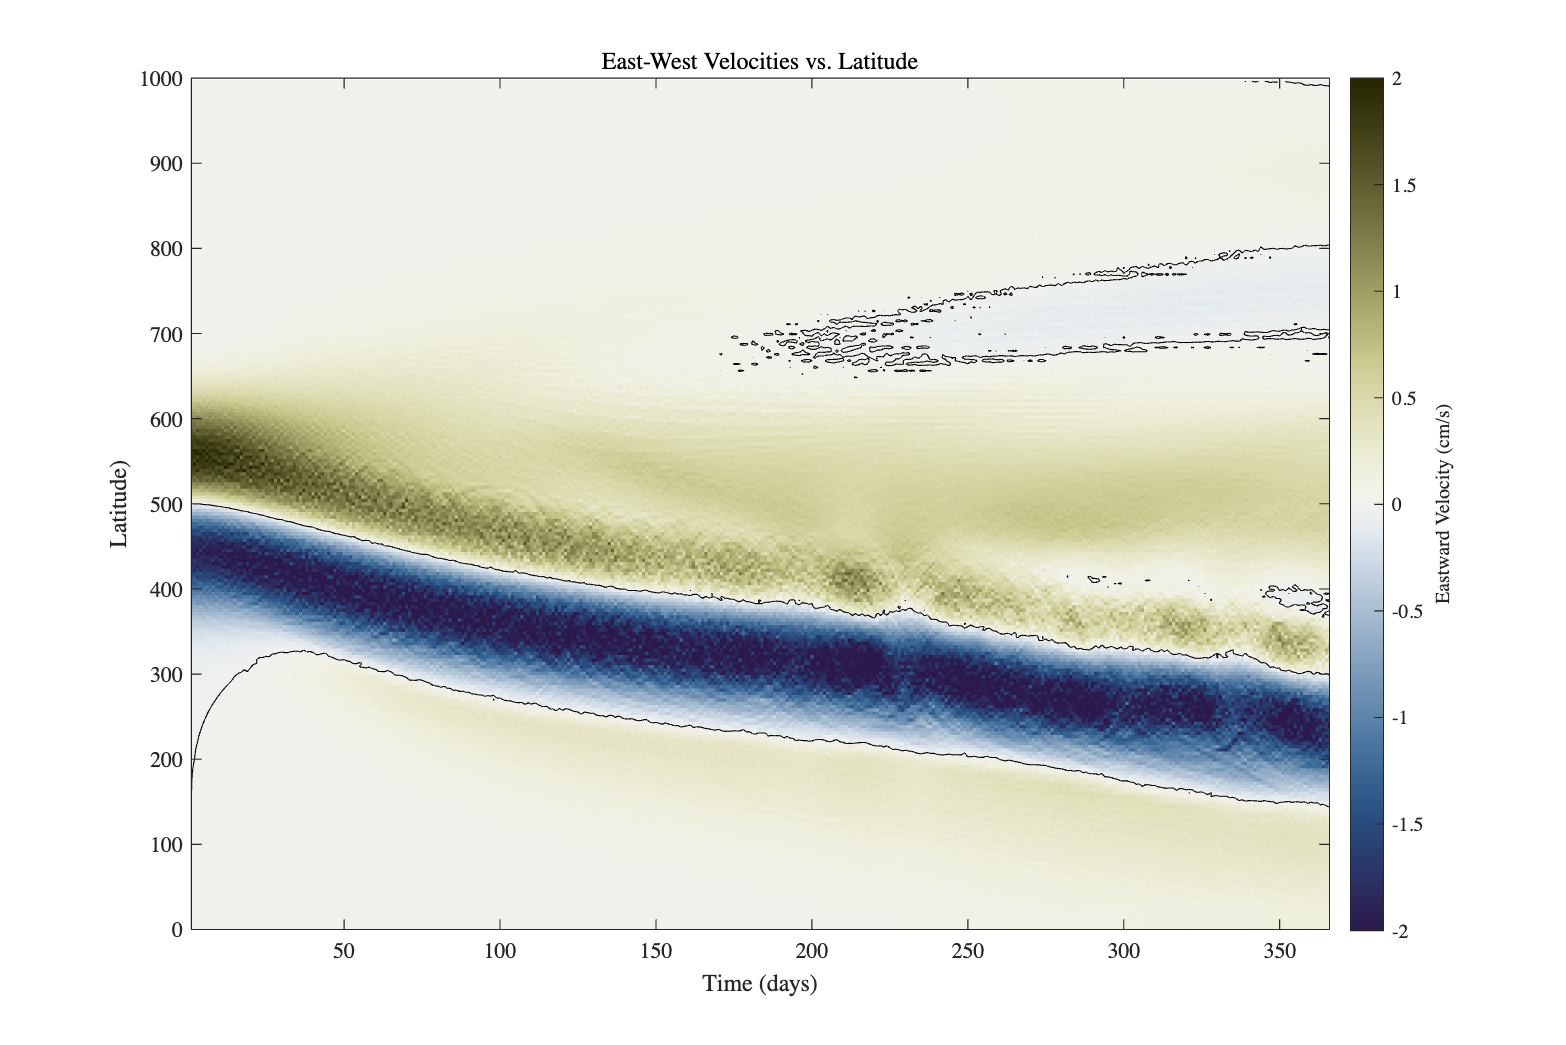

xbins=[0.5:1:size(drifter_x,1)+0.5];
dy=y(2)-y(1);
ybins=min(y)-dy/2:dy:max(y)+dy/2;
[mz,xmid,ymid,numz,stdz]=twodstats(drifter_t,drifter_y,drifter_u,xbins,ybins);

hf = figure();
hf.Position(3:4) = [1200,800];
colormap(crameri('broc'))

jpcolor(xmid,ymid,mz)
colormap(crameri('broc'))
clim([-.02 .02]*100),
hold on,contour(xmid,ymid,mz,[0 0],'k')
title('East-West Velocities vs. Latitude')
hc=colorbar('location','EastOutside');
hc.Label.String = "Eastward Velocity (cm/s)";
axis([1 366 0 1000])

xlabel("Time (days)")
ylabel("Latitude)")

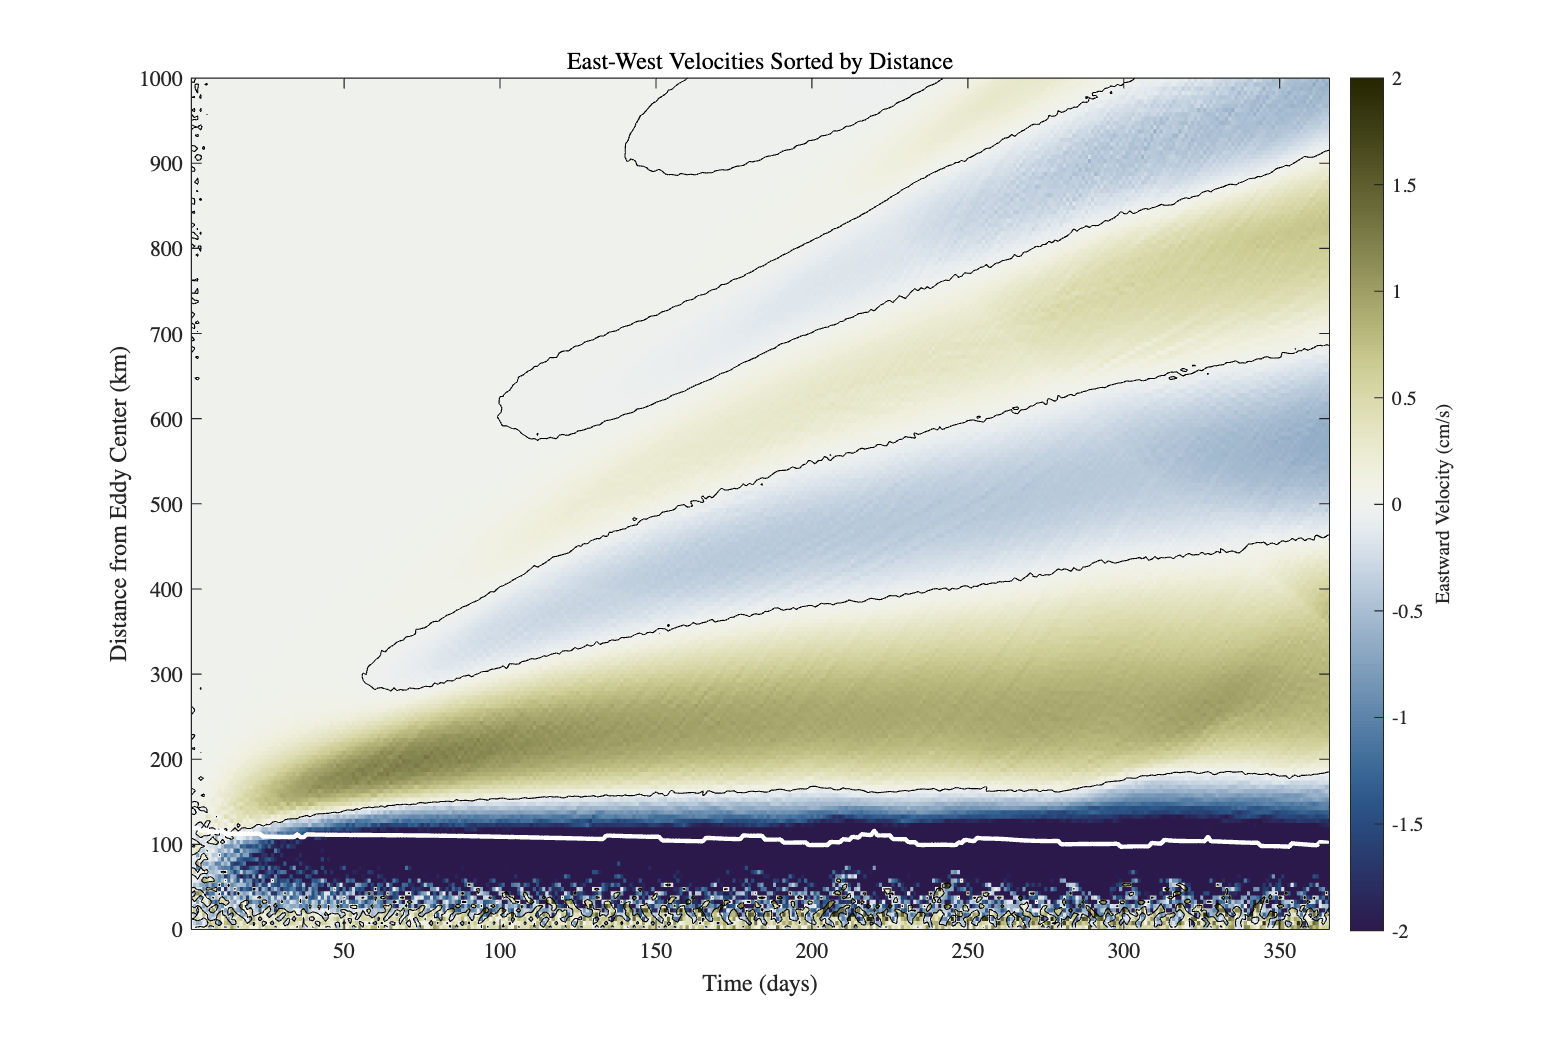

%finally we will look at the east-west transport sorted by distance
xbins=[0.5:1:size(drifter_x,1)+0.5];

drifter_d=zeros(size(drifter_t));
for k=1:size(drifter_d,1)
    %note! should used periodized distance, which matters for very large distances
    drifter_d(k,:)=sqrt((drifter_x(k,:)-xo(k)).^2+(drifter_y(k,:)-yo(k)).^2);
end

dbins=[0:5:max(drifter_d,[],"all")];
[mz,xmid,ymid,numz,stdz]=twodstats(drifter_t,drifter_d,drifter_u,xbins,dbins);

hf = figure();
hf.Position(3:4) = [1200,800];
colormap(crameri('broc'))

jpcolor(xmid,ymid,mz)
colormap(crameri('broc'))
clim([-.02 .02]*100),
hold on,contour(xmid,ymid,mz,[0 0],'k')
title('East-West Velocities Sorted by Distance')
hc=colorbar('location','EastOutside');
hc.Label.String = "Eastward Velocity (cm/s)";
axis([1 366 0 1000])
plot(1:length(R),R,'w','linewidth',2)

xlabel("Time (days)")
ylabel("Distance from Eddy Center (km)")

Let's look at the zonally averaged properties centered on the eddy. 

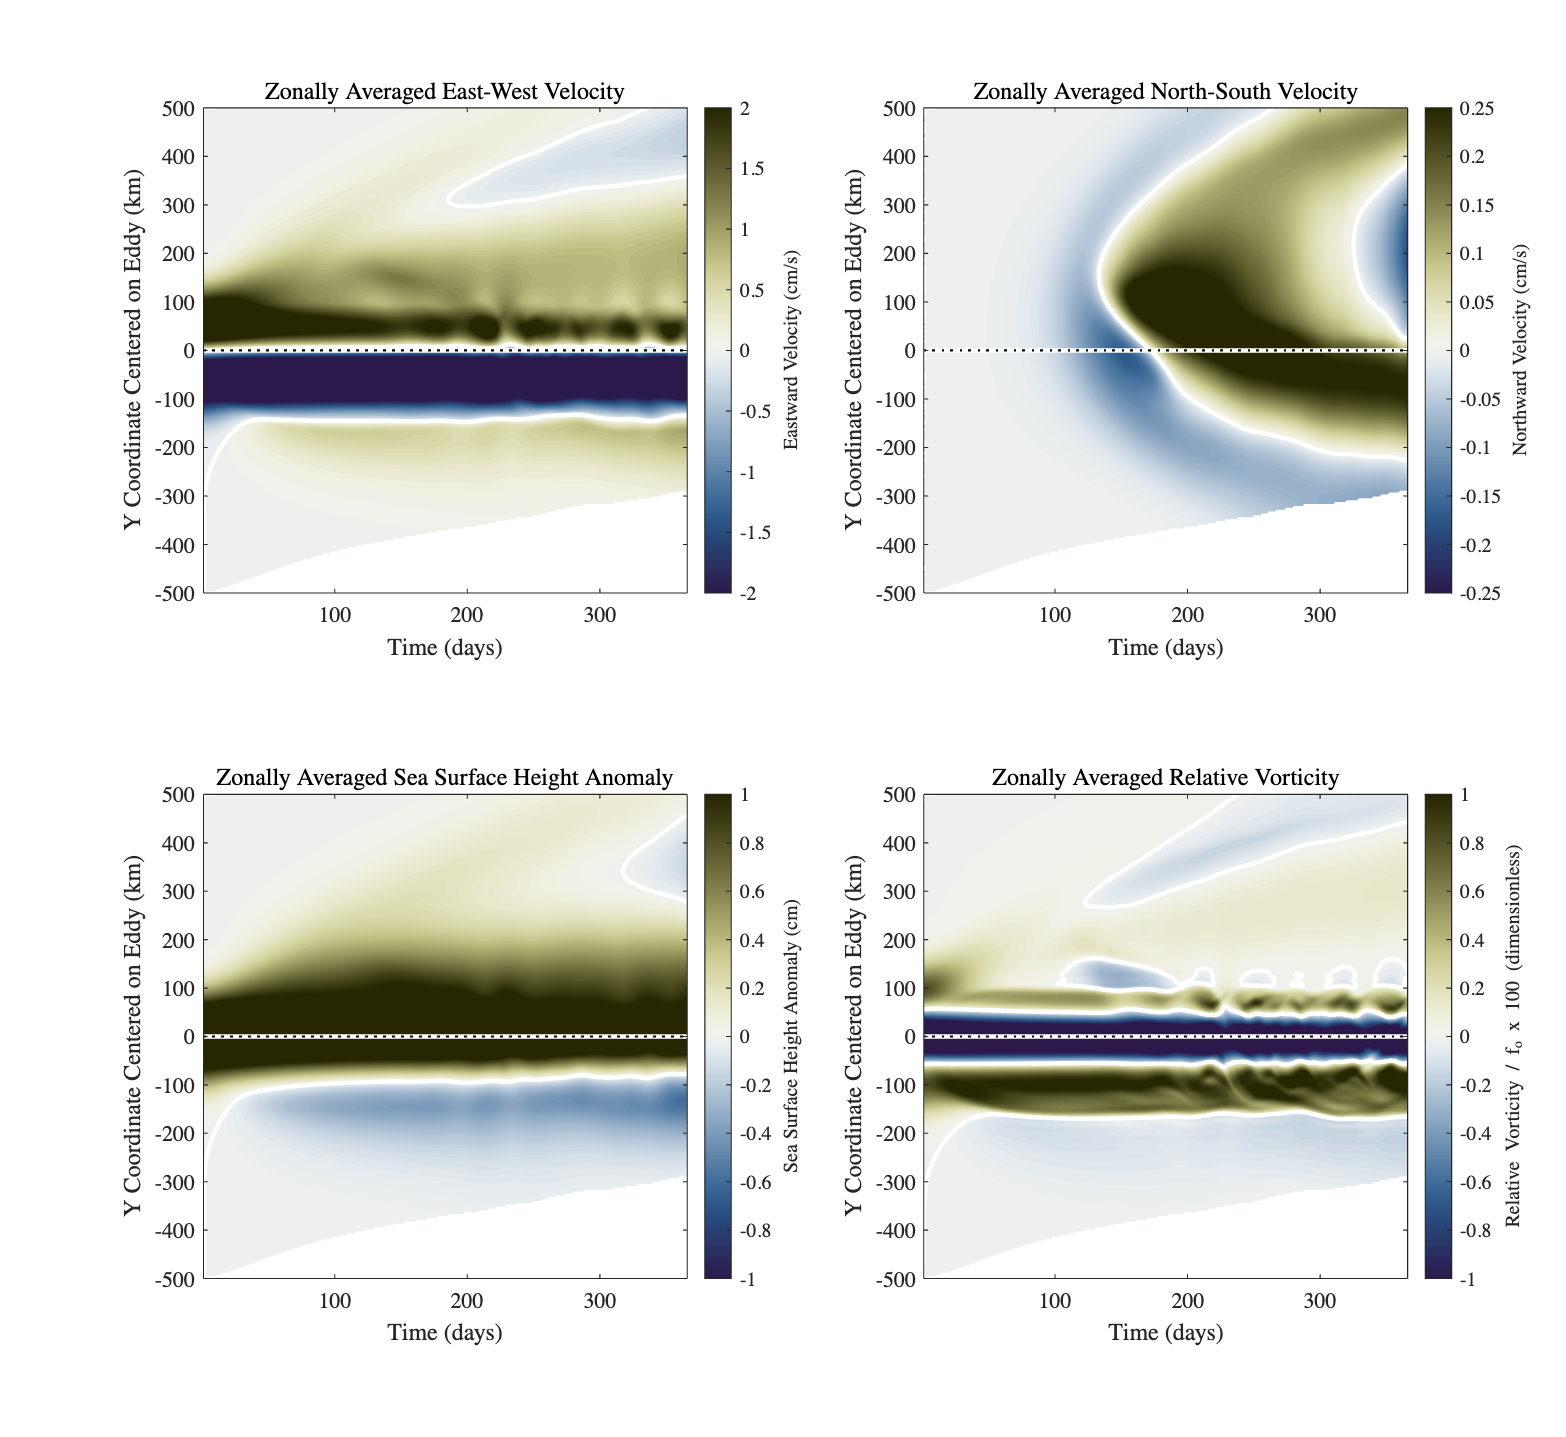

[xp2,yp2,sshF,uF,vF,zetaF]=fieldInEddyFrame(x,y,xo,yo,1000,ssh,u,v,zeta);

hf = figure();
hf.Position(3:4) = [1200,1100];
colormap(crameri('broc'))

tiledlayout(2,2);

nexttile
contourf(1:size(ssh,3),yp2,squeeze(mean(uF,1,'omitmissing')),200);nocontours, hold on
contour(1:size(ssh,3),yp2,squeeze(mean(uF,1,'omitmissing')),[0 0],'w',linewidth=2);
xlabel('Time (days)'),ylabel('Y Coordinate Centered on Eddy (km)')
title('Zonally Averaged East-West Velocity')
hc=colorbar('location','EastOutside');
hc.Label.String = "Eastward Velocity (cm/s)";
clim([-2 2]),hlines(0,'2w'),hlines(0,'k:')

nexttile
contourf(1:size(ssh,3),yp2,squeeze(mean(vF,1,'omitmissing')),200);nocontours, hold on
contour(1:size(ssh,3),yp2,squeeze(mean(vF,1,'omitmissing')),[0 0],'w',linewidth=2);
xlabel('Time (days)'),ylabel('Y Coordinate Centered on Eddy (km)')
title('Zonally Averaged North-South Velocity')
hc=colorbar('location','EastOutside');
hc.Label.String = "Northward Velocity (cm/s)";
clim([-2 2]/8),hlines(0,'2w'),hlines(0,'k:')

nexttile
contourf(1:size(ssh,3),yp2,squeeze(mean(sshF,1,'omitmissing')),200);nocontours, hold on
contour(1:size(ssh,3),yp2,squeeze(mean(sshF,1,'omitmissing')),[0 0],'w',linewidth=2);
xlabel('Time (days)'),ylabel('Y Coordinate Centered on Eddy (km)')
title('Zonally Averaged Sea Surface Height Anomaly')
hc=colorbar('location','EastOutside');
hc.Label.String = "Sea Surface Height Anomaly (cm)";
clim([-1 1]),hlines(0,'2w'),hlines(0,'k:')

nexttile
contourf(1:size(ssh,3),yp2,100*squeeze(mean(zetaF,1,'omitmissing')),200);nocontours, hold on
contour(1:size(ssh,3),yp2,100*squeeze(mean(zetaF,1,'omitmissing')),[0 0],'w',linewidth=2);
xlabel('Time (days)'),ylabel('Y Coordinate Centered on Eddy (km)')
title('Zonally Averaged Relative Vorticity')
hc=colorbar('location','EastOutside');
hc.Label.String = "Relative Vorticity / f_o x 100 (dimensionless)";
clim([-1 1]),hlines(0,'2w'),hlines(0,'k:')